# Thermodynamically constrain a metabololic model

## **Author: Ronan Fleming, University of Luxembourg**

## **Reviewers: **

## INTRODUCTION

In flux balance analysis of genome scale stoichiometric models of metabolism, the principal constraints are uptake or secretion rates, the steady state mass conservation assumption and reaction directionality. Von Bertylanffy [1,4] is a set of methods for (i) quantitative estimation of thermochemical parameters for metabolites and reactions using the component contribution method [3], (ii) quantitative assignment of reaction directionality in a multi-compartmental genome scale model based on an application of the second law of thermodynamics to each reaction [2], (iii) analysis of thermochemical parameters in a network context, and (iv) thermodynamically constrained flux balance analysis. The theoretical basis for each of these methods is detailed within the cited papers.

**EQUIPMENT**

Ubuntu 16.04 LTS

Python 2.7

NumPy 1.11.1

ChemAxon MarvinBeans 16.9.5.0

OpenBabel 2.3

**EQUIPMENT SETUP**

The following commands are entered in a terminal window (bash or similar shell).

## Python 2 

OpenBabel only works with Python 2. Most distributions should already have this installed, but if this is not the case, the following lines will do it: 

sudo add-apt-repository ppa:fkrull/deadsnakes  

sudo apt-get update  

sudo apt-get install python2.7

## NumPy 

NumPy can be installed using the following commands: 

sudo apt-get install python-dev 

sudo apt-get install python-setuptools 

sudo wget http://downloads.sourceforge.net/project/numpy/NumPy/1.11.1/numpy-1.11.1.tar.gz  

sudo tar -xzvf numpy-1.11.1.tar.gz 

sudo cd numpy-1.11.1  

sudo python setup.py build -j 4 install 

## ChemAxon Calculator Plugin 

ChemAxon calculator plugin requires a license. Apply for an academic license at the following link: http://www.chemaxon.com/my-chemaxon/my-academic-license/ 

After your license has been made available, you can download from the “My Licenses” tab on the ChemAxon website. 

Download the license and place it under (replace USER by your actual user account): 

/home/USER/.chemaxon 

Download MarvinBeans for Linux, navigate to the directory where it was saved and make it executable (here, we downloaded version 16.9.5.0 - use the appropriate filename for your version):  

sudo chmod +x marvinbeans-16.9.5.0-linux_with_jre64.sh  

Execute the installer (again, use the same filename as above): 

sudo ./marvinbeans-16.9.5.0-linux_with_jre64.sh 

When asked for an installation directory, make it:  

/opt/ChemAxon/MarvinBeans 

This is important, since this is the path used by COBRA Toolbox. 

Finally, add the installation path to the PATH environment variable: 

PATH=$PATH:/opt/ChemAxon/MarvinBeans/bin 

sudo export PATH

## OpenBabel and Python bindings  

Install the OpenBabel and Python 2 bindings by entering the following: 

sudo apt-get install openbabel  

sudo apt-get install python-openbabel

## PROCEDURE

## Configure the environment

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

if 1
    initVonBertalanffy
end

# Select the model

This tutorial is tested for the E. coli model iAF1260 and the human metabolic model Recon3.0model. However, only the data for the former is provided within the COBRA Toolbox as it is used for testing von Bertylanffy, while Recon3D is not yet published and the data is not yet available. Having said this, the figures generated below are most suited to plotting results for Recon3Dmodel, so they may not be so useful for iAF1260.  The Recon3Dmodel example uses values from literature for input variables where they are available.

modelName='iAF1260';
% modelName='Recon3.0model'; uncomment this line and comment the line above if you want to use Recon3D

## Load a model

Load a model, and save it as the original model in the workspace, unless it is already loaded into the workspace. 

clear model
global CBTDIR
modelFileName = [modelName '.mat']
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);
switch modelName
    case 'iAF1260'
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[c]', model.mets))=0; % One reaction needing charge balancing
        
    case 'Recon3.0model'
        model.metFormulas{strcmp(model.mets,'h[i]')}='H';
        model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
    otherwise
            error('setup specific parameters for your model')
end

## Set the directory containing the results

switch modelName
    case 'iAF1260'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'Recon3.0model'
        basePath='~/work/sbgCloud';
        resultsPath=[basePath '/programReconstruction/projects/recon2models/results/thermo/' modelName];
        resultsBaseFileName=[resultsPath filesep modelName '_' datestr(now,30) '_'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the directory containing molfiles

switch modelName
    case 'iAF1260'
        molfileDir = 'iAF1260Molfiles';
    case 'Recon3.0model'
        molfileDir = [basePath '/data/molFilesDatabases/explicitHMol'];
        %molfileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBimplicitHMol'];
        %molfileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBexplicitHMol'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the thermochemical parameters for the model

switch modelName
    case 'iAF1260'
        T = 310.15; % Temperature in Kelvin
        compartments = ['c'; 'e'; 'p']; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV
    case 'Recon3.0model'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    otherwise
        error('setup specific parameters for your model')
end

## Set the default range of metabolite concentrations

switch modelName
    case 'iAF1260'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'Recon3.0model'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    otherwise
        error('setup specific parameters for your model')
end

## Set the desired confidence level for estimation of thermochemical parameters

The confidence level for estimated standard transformed reaction Gibbs energies is used to quantitatively assign reaction directionality.

switch modelName
    case 'iAF1260'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    case 'Recon3.0model'
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    otherwise
        error('setup specific parameters for your model')
end

## Prepare folder for results

if ~exist(resultsPath,'dir')
    mkdir(resultsPath)
end
cd(resultsPath)

## Set the print level and decide to record a diary or not (helpful for debugging)

printLevel=2;
if 1
    diary([resultsPath filesep 'diary.txt'])
end

# Setup a thermodynamically constrained model

## Read in the metabolite bounds

if 1
    setDefaultConc=1;
    setDefaultFlux=0;
    rxnBoundsFile=[];
    model=readMetRxnBoundsFiles(model,setDefaultConc,setDefaultFlux,concMinDefault,concMaxDefault,metBoundsFile,rxnBoundsFile,printLevel);
end

## Check inputs

model = configureSetupThermoModelInputs(model,T,compartments,ph,is,chi,concMinDefault,concMaxDefault,confidenceLevel);

## Check elemental balancing of metabolic reactions

ignoreBalancingOfSpecifiedInternalReactions=1;
if ~exist('massImbalance','var')
    if isfield(model,'Srecon')
        model.S=model.Srecon;
    end
    % Check for imbalanced reactions
    fprintf('\nChecking mass and charge balance.\n');
    %Heuristically identify exchange reactions and metabolites exclusively involved in exchange reactions
    if ~isfield(model,'SIntMetBool')  ||  ~isfield(model,'SIntRxnBool') || ignoreBalancingOfSpecifiedInternalReactions
        %finds the reactions in the model which export/import from the model
        %boundary i.e. mass unbalanced reactions
        %e.g. Exchange reactions
        %     Demand reactions
        %     Sink reactions
        model = findSExRxnInd(model,[],printLevel);
    end
    
    if ignoreBalancingOfSpecifiedInternalReactions
        [nMet,nRxn]=size(model.S);
        ignoreBalancingMetBool=false(nMet,1);
        for m=1:nMet
%             if strcmp(model.mets{m},'Rtotal3coa[m]')
%                 pause(0.1);
%             end
            if ~isempty(model.metFormulas{m})
                ignoreBalancingMetBool(m,1)=numAtomsOfElementInFormula(model.metFormulas{m},'FULLR');
            end
        end
        ignoreBalancingRxnBool=getCorrespondingCols(model.S,ignoreBalancingMetBool,model.SIntRxnBool,'inclusive');
        SIntRxnBool=model.SIntRxnBool;
        model.SIntRxnBool=model.SIntRxnBool & ~ignoreBalancingRxnBool;
    end
    
    printLevelcheckMassChargeBalance=-1;  % -1; % print problem reactions to a file
    %mass and charge balance can be checked by looking at formulas
    [massImbalance,imBalancedMass,imBalancedCharge,imBalancedRxnBool,Elements,missingFormulaeBool,balancedMetBool]...
        = checkMassChargeBalance(model,printLevelcheckMassChargeBalance,resultsBaseFileName);
    model.balancedRxnBool=~imBalancedRxnBool;
    model.balancedMetBool=balancedMetBool;
    model.Elements=Elements;
    model.missingFormulaeBool=missingFormulaeBool;
    
    %reset original boolean vector
    if ignoreBalancingOfSpecifiedInternalReactions
        model.SIntRxnBool=SIntRxnBool;
    end
end

## Check that the input data necessary for the component contribution method is in place

if 1 %isfield(model,'pseudoisomers')
    model = setupComponentContribution(model,molfileDir);
end

Creating MetStructures.sdf from molfiles.
Percentage of metabolites without mol files: 100.0%
Converting SDF to InChI strings.
Estimating metabolite pKa values.
Assuming that metabolite species in model.metFormulas are representative for metabolites where pKa could not be estimated.


## Prepare the training data for the component contribution method


%if ~exist('training_data','var')
    training_data = prepareTrainingData(model,printLevel);

Successfully added 3914 values from TECRDB
Successfully added 223 formation energies
Successfully added 13 redox potentials
Loading the InChIs for the training data from: /Users/zuck016/Projects/src/mycobratoolbox/src/analysis/thermo/componentContribution/cache/kegg_inchies.mat
Successfully created balanced training-data structure: 672 compounds and 4138 reactions
Loading the pKa values for the training data from: cache/kegg_pkas.mat
Mapping model metabolites to nist compounds
Creating group incidence matrix
python2 /Users/zuck016/Projects/src/mycobratoolbox/src/analysis/thermo/componentContribution/inchi2gv.py -s -i "InChI=1/C18H22O2/c1-18-9-8-14-13-5-3-12(19)10-11(13)2-4-15(14)16(18)6-7-17(18)20/h3,5,10,14-16,19H,2,4,6-9H2,1H3/t14-,15-,16+,18+/m1/s1": Signal 127
python2 /Users/zuck016/Projects/src

%end

## Call the component contribution method

if ~isfield(model,'DfG0')
    [model,~] = componentContribution(model,training_data);
end

Running Component Contribution method


## Setup a thermodynamically constrained model

if ~isfield(model,'DfGt0')
    model = setupThermoModel(model,confidenceLevel);
end


Estimating standard transformed Gibbs energies of formation.

Estimating bounds on transformed Gibbs energies.
Additional effect due to possible change in chemical potential of Hydrogen ions for transport reactions.
Additional effect due to possible change in electrical potential for transport reactions.


## Generate a model with reactants instead of major microspecies

if ~isfield(model,'Srecon') 
    printLevel_pHbalanceProtons=-1;

    model=pHbalanceProtons(model,massImbalance,printLevel_pHbalanceProtons,resultsBaseFileName);
end

## Determine quantitative directionality assignments

if ~exist('directions','var')
    fprintf('Quantitatively assigning reaction directionality.\n');
    [modelThermo, directions] = thermoConstrainFluxBounds(model,confidenceLevel,DrGt0_Uncertainty_Cutoff,printLevel);
end

Quantitatively assigning reaction directionality.


3/2382 reactions with DrGtMin=DrGtMax=0
4 inactive reactions (lb = ub = 0)
The following reactions have DrGtMax=DrGtMin=0:
H2Otex	h2o[e] 	<=>	h2o[p] 
H2Otpp	h2o[p] 	<=>	h2o[c] 
Htex	h[e] 	<=>	h[p] 


## Analyse thermodynamically constrained model

Choose the cutoff for probablity that reaction is reversible

cumNormProbCutoff=0.2;

Build Boolean vectors with reaction directionality statistics

[modelThermo,directions]=directionalityStats(modelThermo,directions,cumNormProbCutoff,printLevel);

3/2382 reactions with DrGtMin=DrGtMax=0
Qualitative internal reaction directionality:
      2077	 internal reconstruction reaction directions.
      1520	 forward reconstruction assignment.
         0	 reverse reconstruction assignment.
       553	 reversible reconstruction assignment.

Quantitative internal reaction directionality:
      2077	 internal reconstruction reaction directions.
       549	 of which have a thermodynamic assignment.
      1525	 of which have no thermodynamic assignment.
        18	 forward thermodynamic only assignment.
         1	 reverse thermodynamic only assignment.
       530	 reversible thermodynamic only assignment.

Qualitiative vs Quantitative:
       334	 Reversible -> Reversible
         0	 Reversible -> Forward
         1	 Reversible -> Reverse
       215	 Reversible -> Uncertain
        17	 Forward -> Forward
         0	 Forward -> Reverse
       195	 Forward -> Reversible
      1308	 Forward -> Uncertain
         0	 Reverse -> Reverse
         0	

% directions    a structue of boolean vectors with different directionality
%               assignments where some vectors contain subsets of others
%
% qualtiative -> quantiative changed reaction directions
%   .forward2Forward
%   .forward2Reverse
%   .forward2Reversible
%   .forward2Uncertain
%   .reversible2Forward
%   .reversible2Reverse
%   .reversible2Reversible
%   .reversible2Uncertain
%   .reverse2Forward
%   .reverse2Reverse
%   .reverse2Reversible
%   .reverse2Uncertain
%   .tightened
%
% subsets of qualtiatively forward  -> quantiatively reversible 
%   .forward2Reversible_bydGt0
%   .forward2Reversible_bydGt0LHS
%   .forward2Reversible_bydGt0Mid
%   .forward2Reversible_bydGt0RHS
% 
%   .forward2Reversible_byConc_zero_fixed_DrG0
%   .forward2Reversible_byConc_negative_fixed_DrG0
%   .forward2Reversible_byConc_positive_fixed_DrG0
%   .forward2Reversible_byConc_negative_uncertain_DrG0
%   .forward2Reversible_byConc_positive_uncertain_DrG0

Write out reports on directionality changes for individual reactions to the results folder.

if 1
    fprintf('%s\n','directionalityChangeReport...');
    directionalityChangeReport(modelThermo,directions,cumNormProbCutoff,printLevel,resultsBaseFileName)
end

directionalityChangeReport...


Generate pie charts with proportions of reaction directionalities and changes in directionality

directionalityStatFigures...


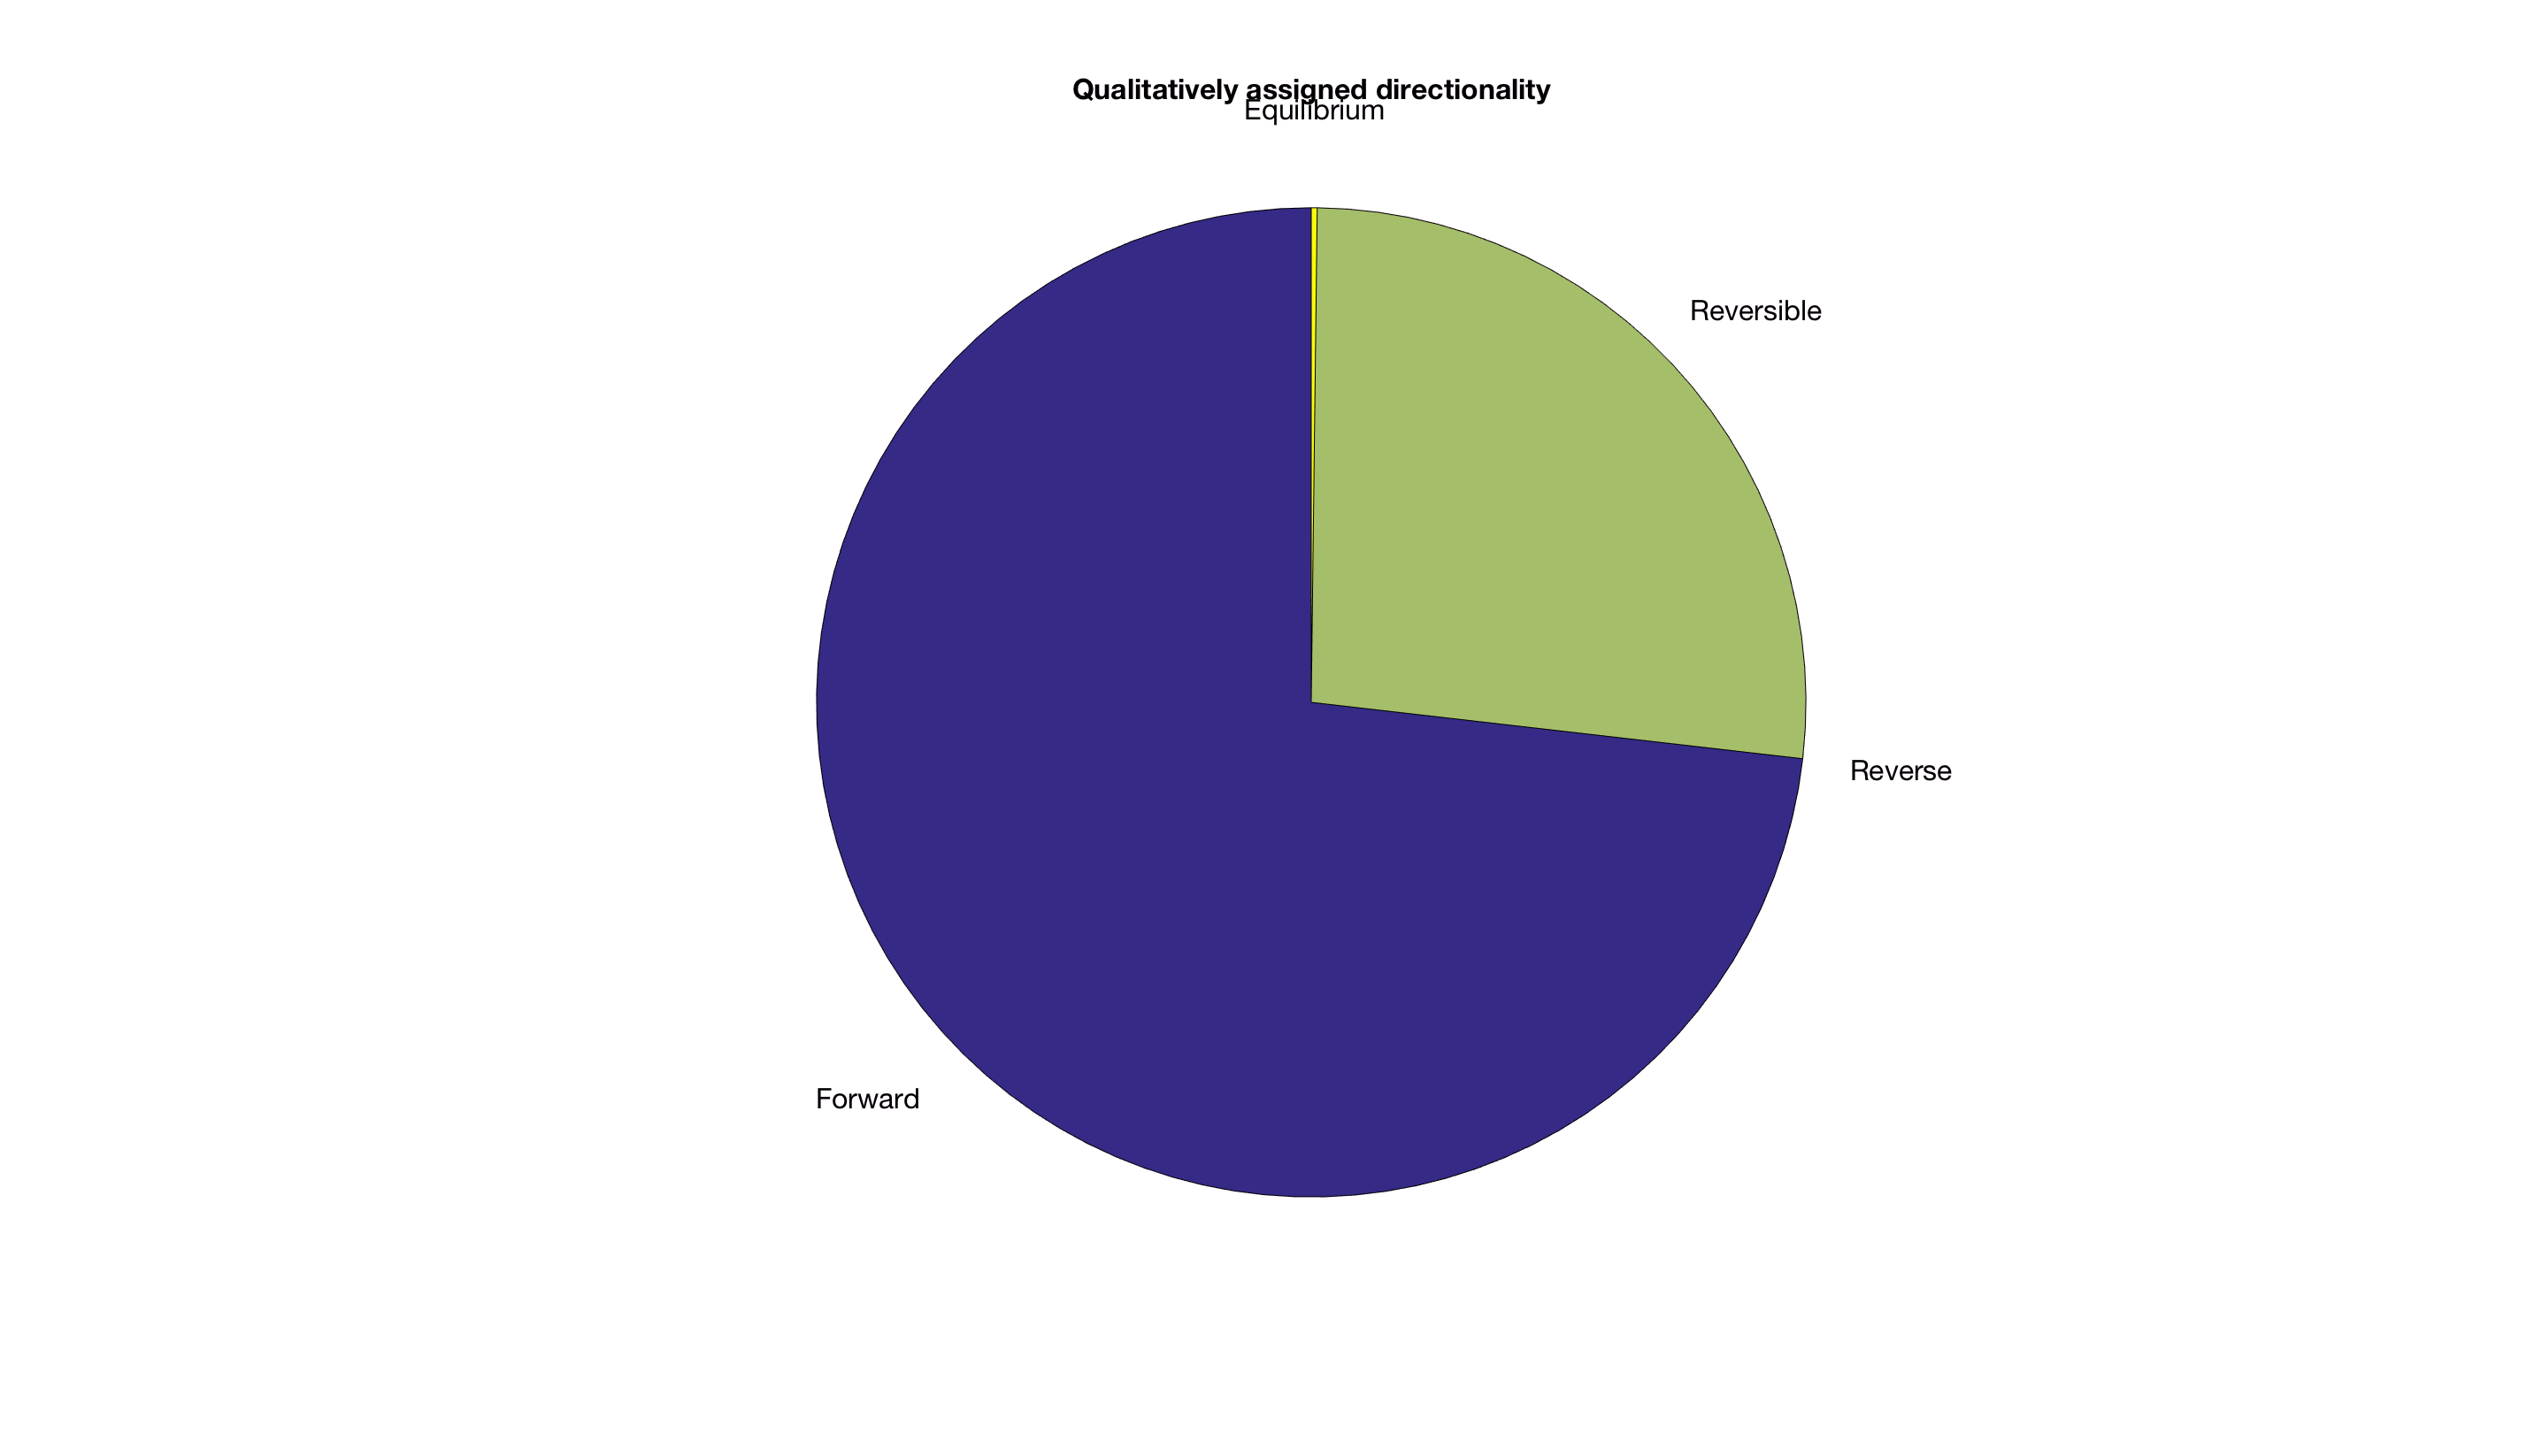

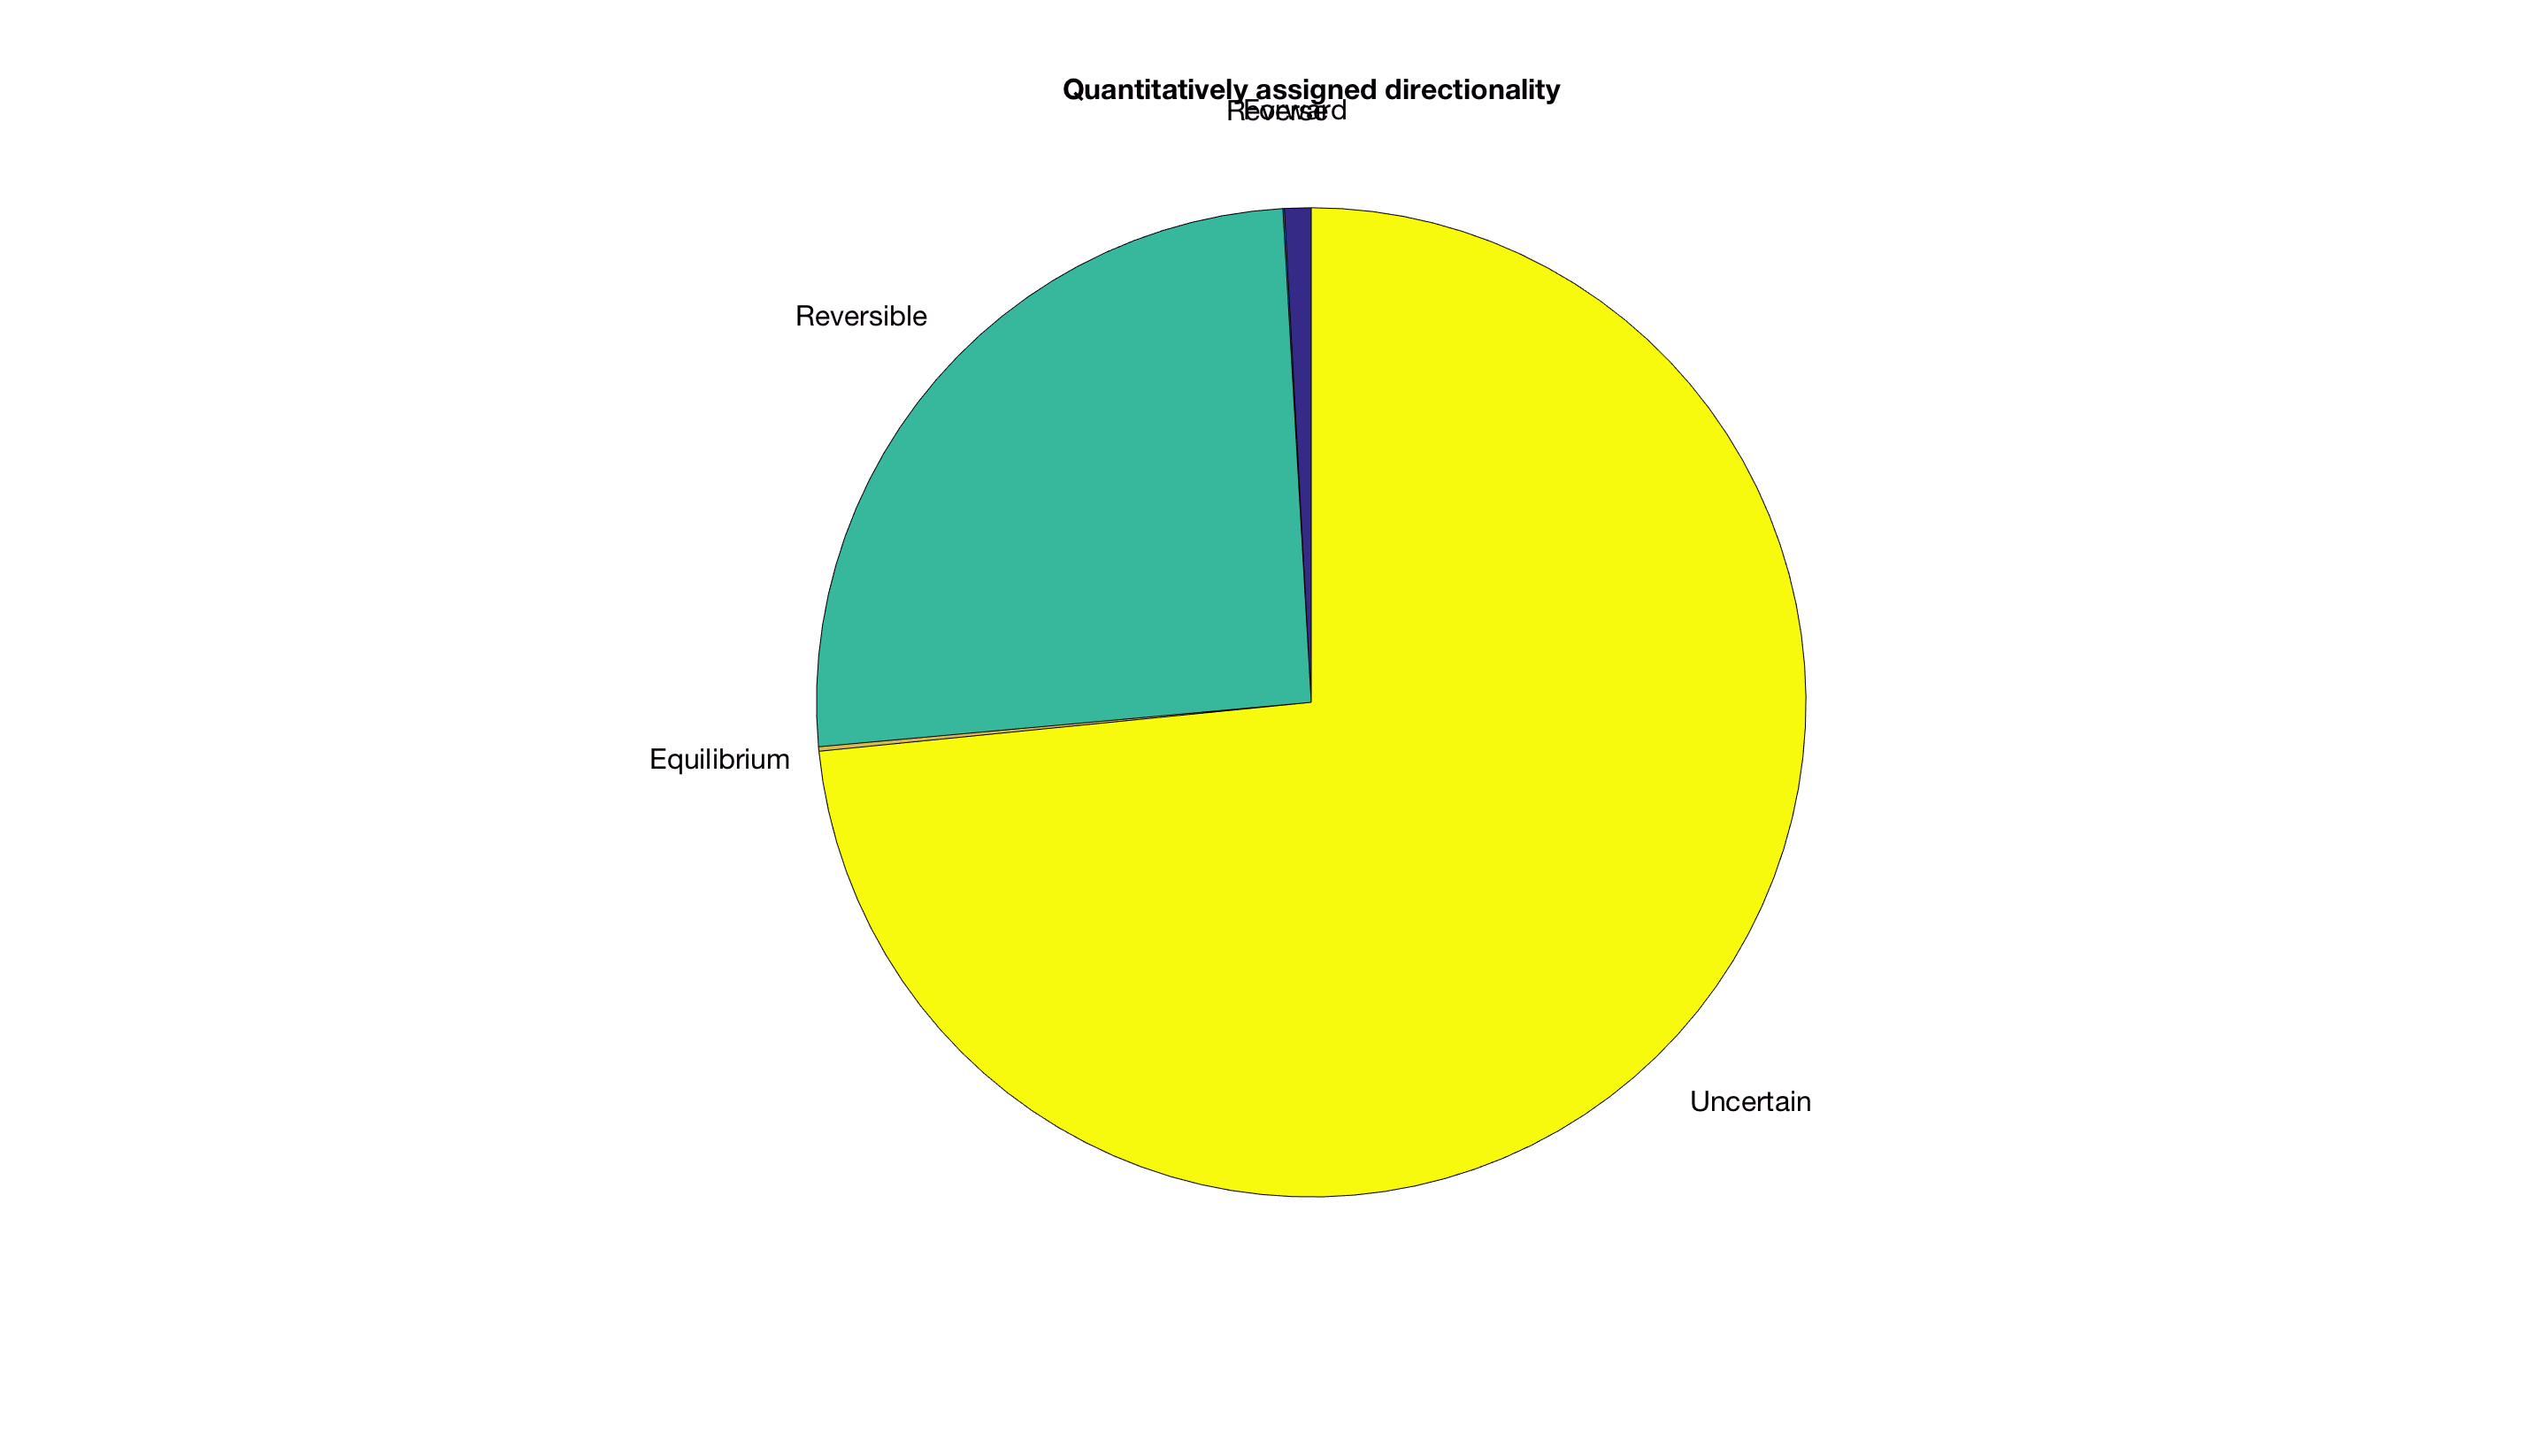

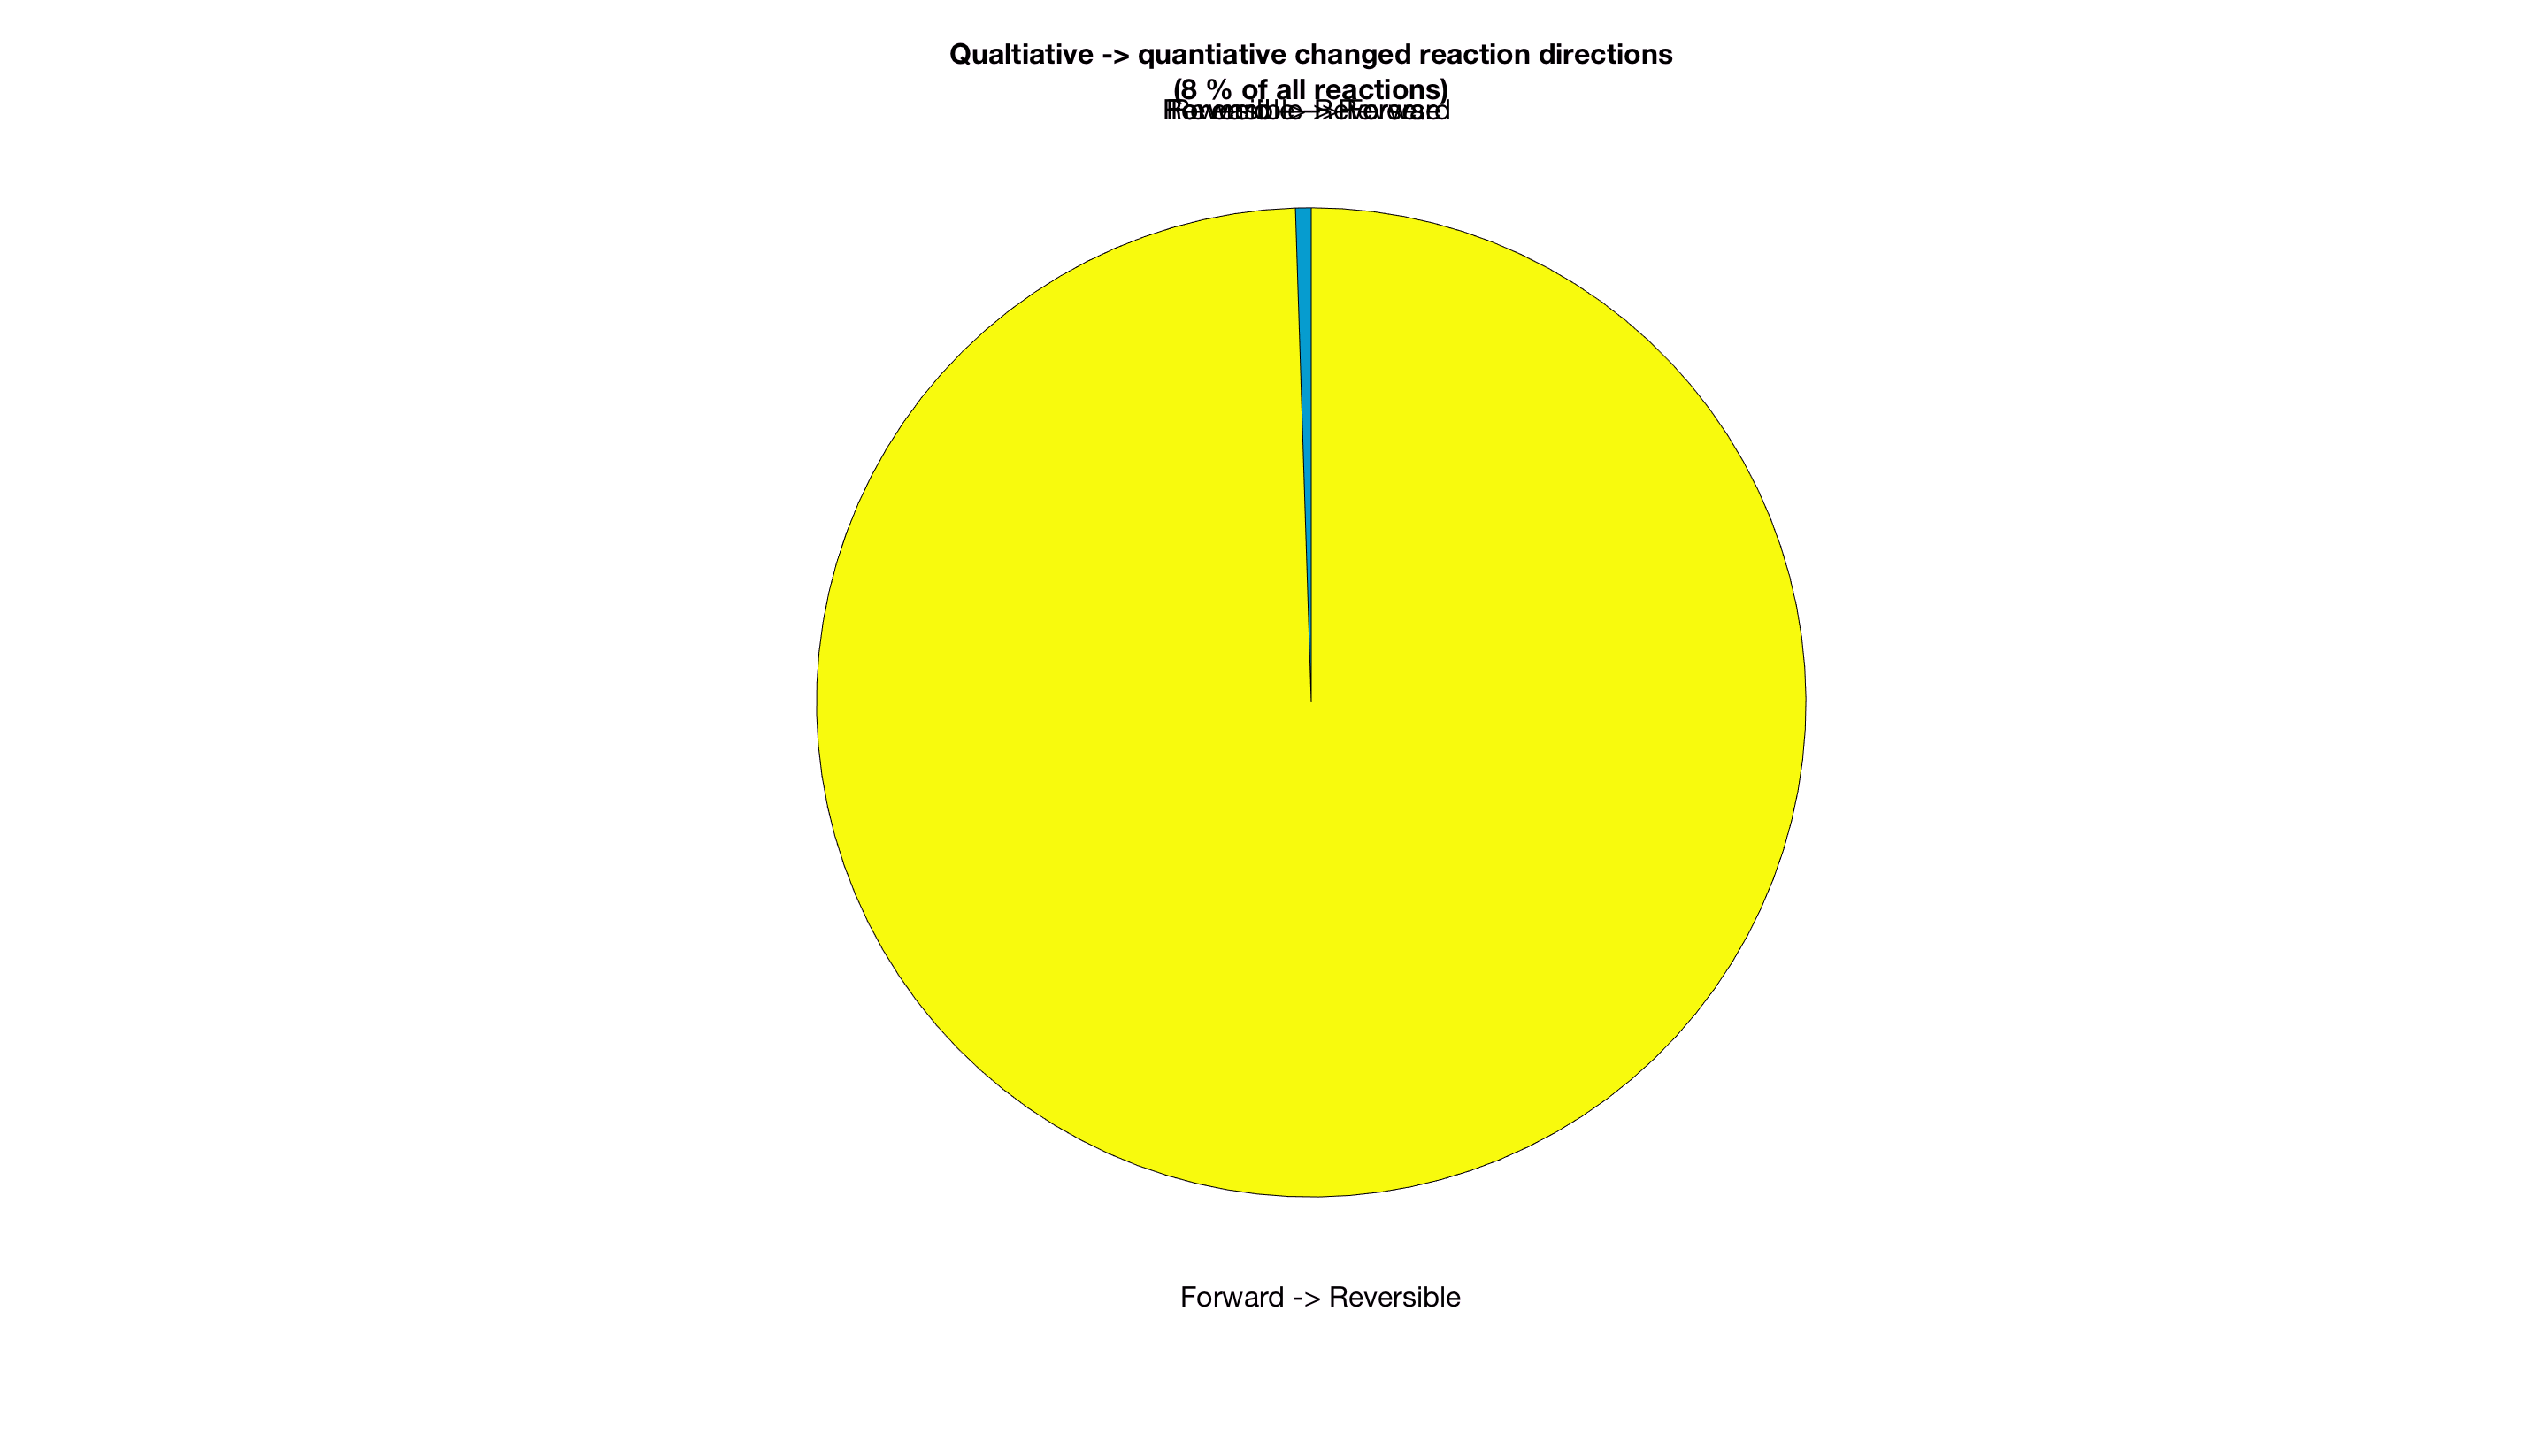

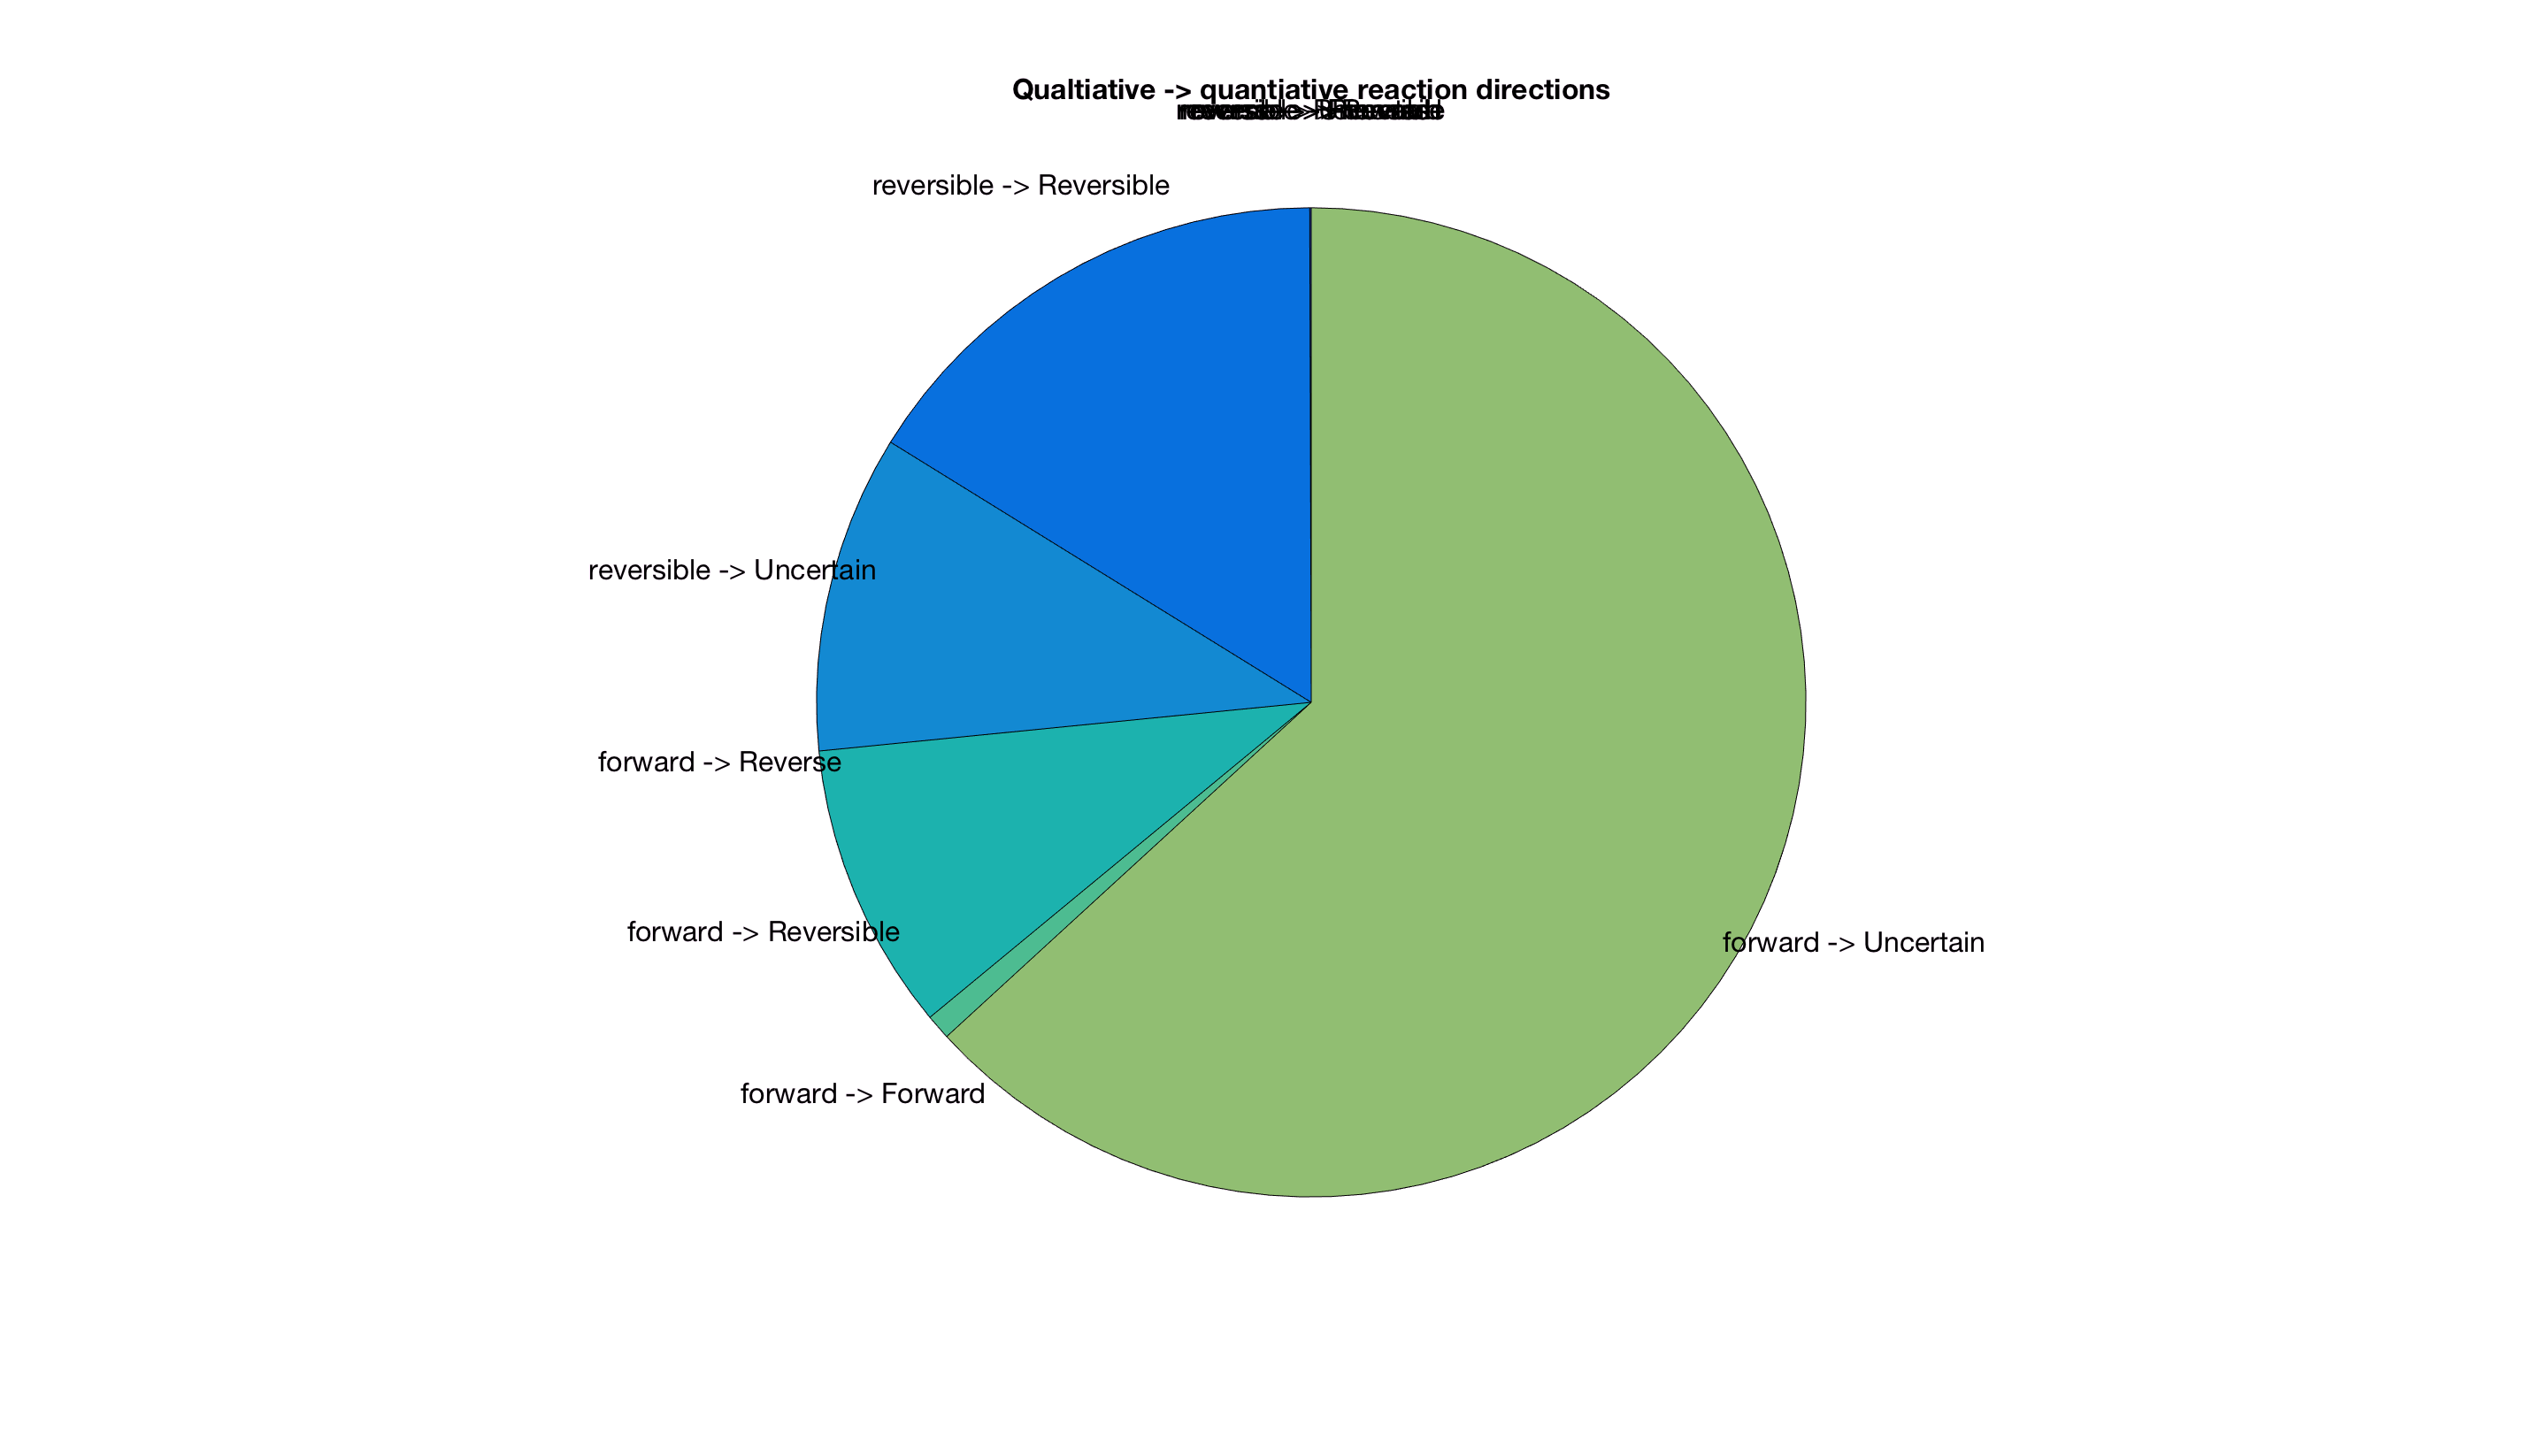

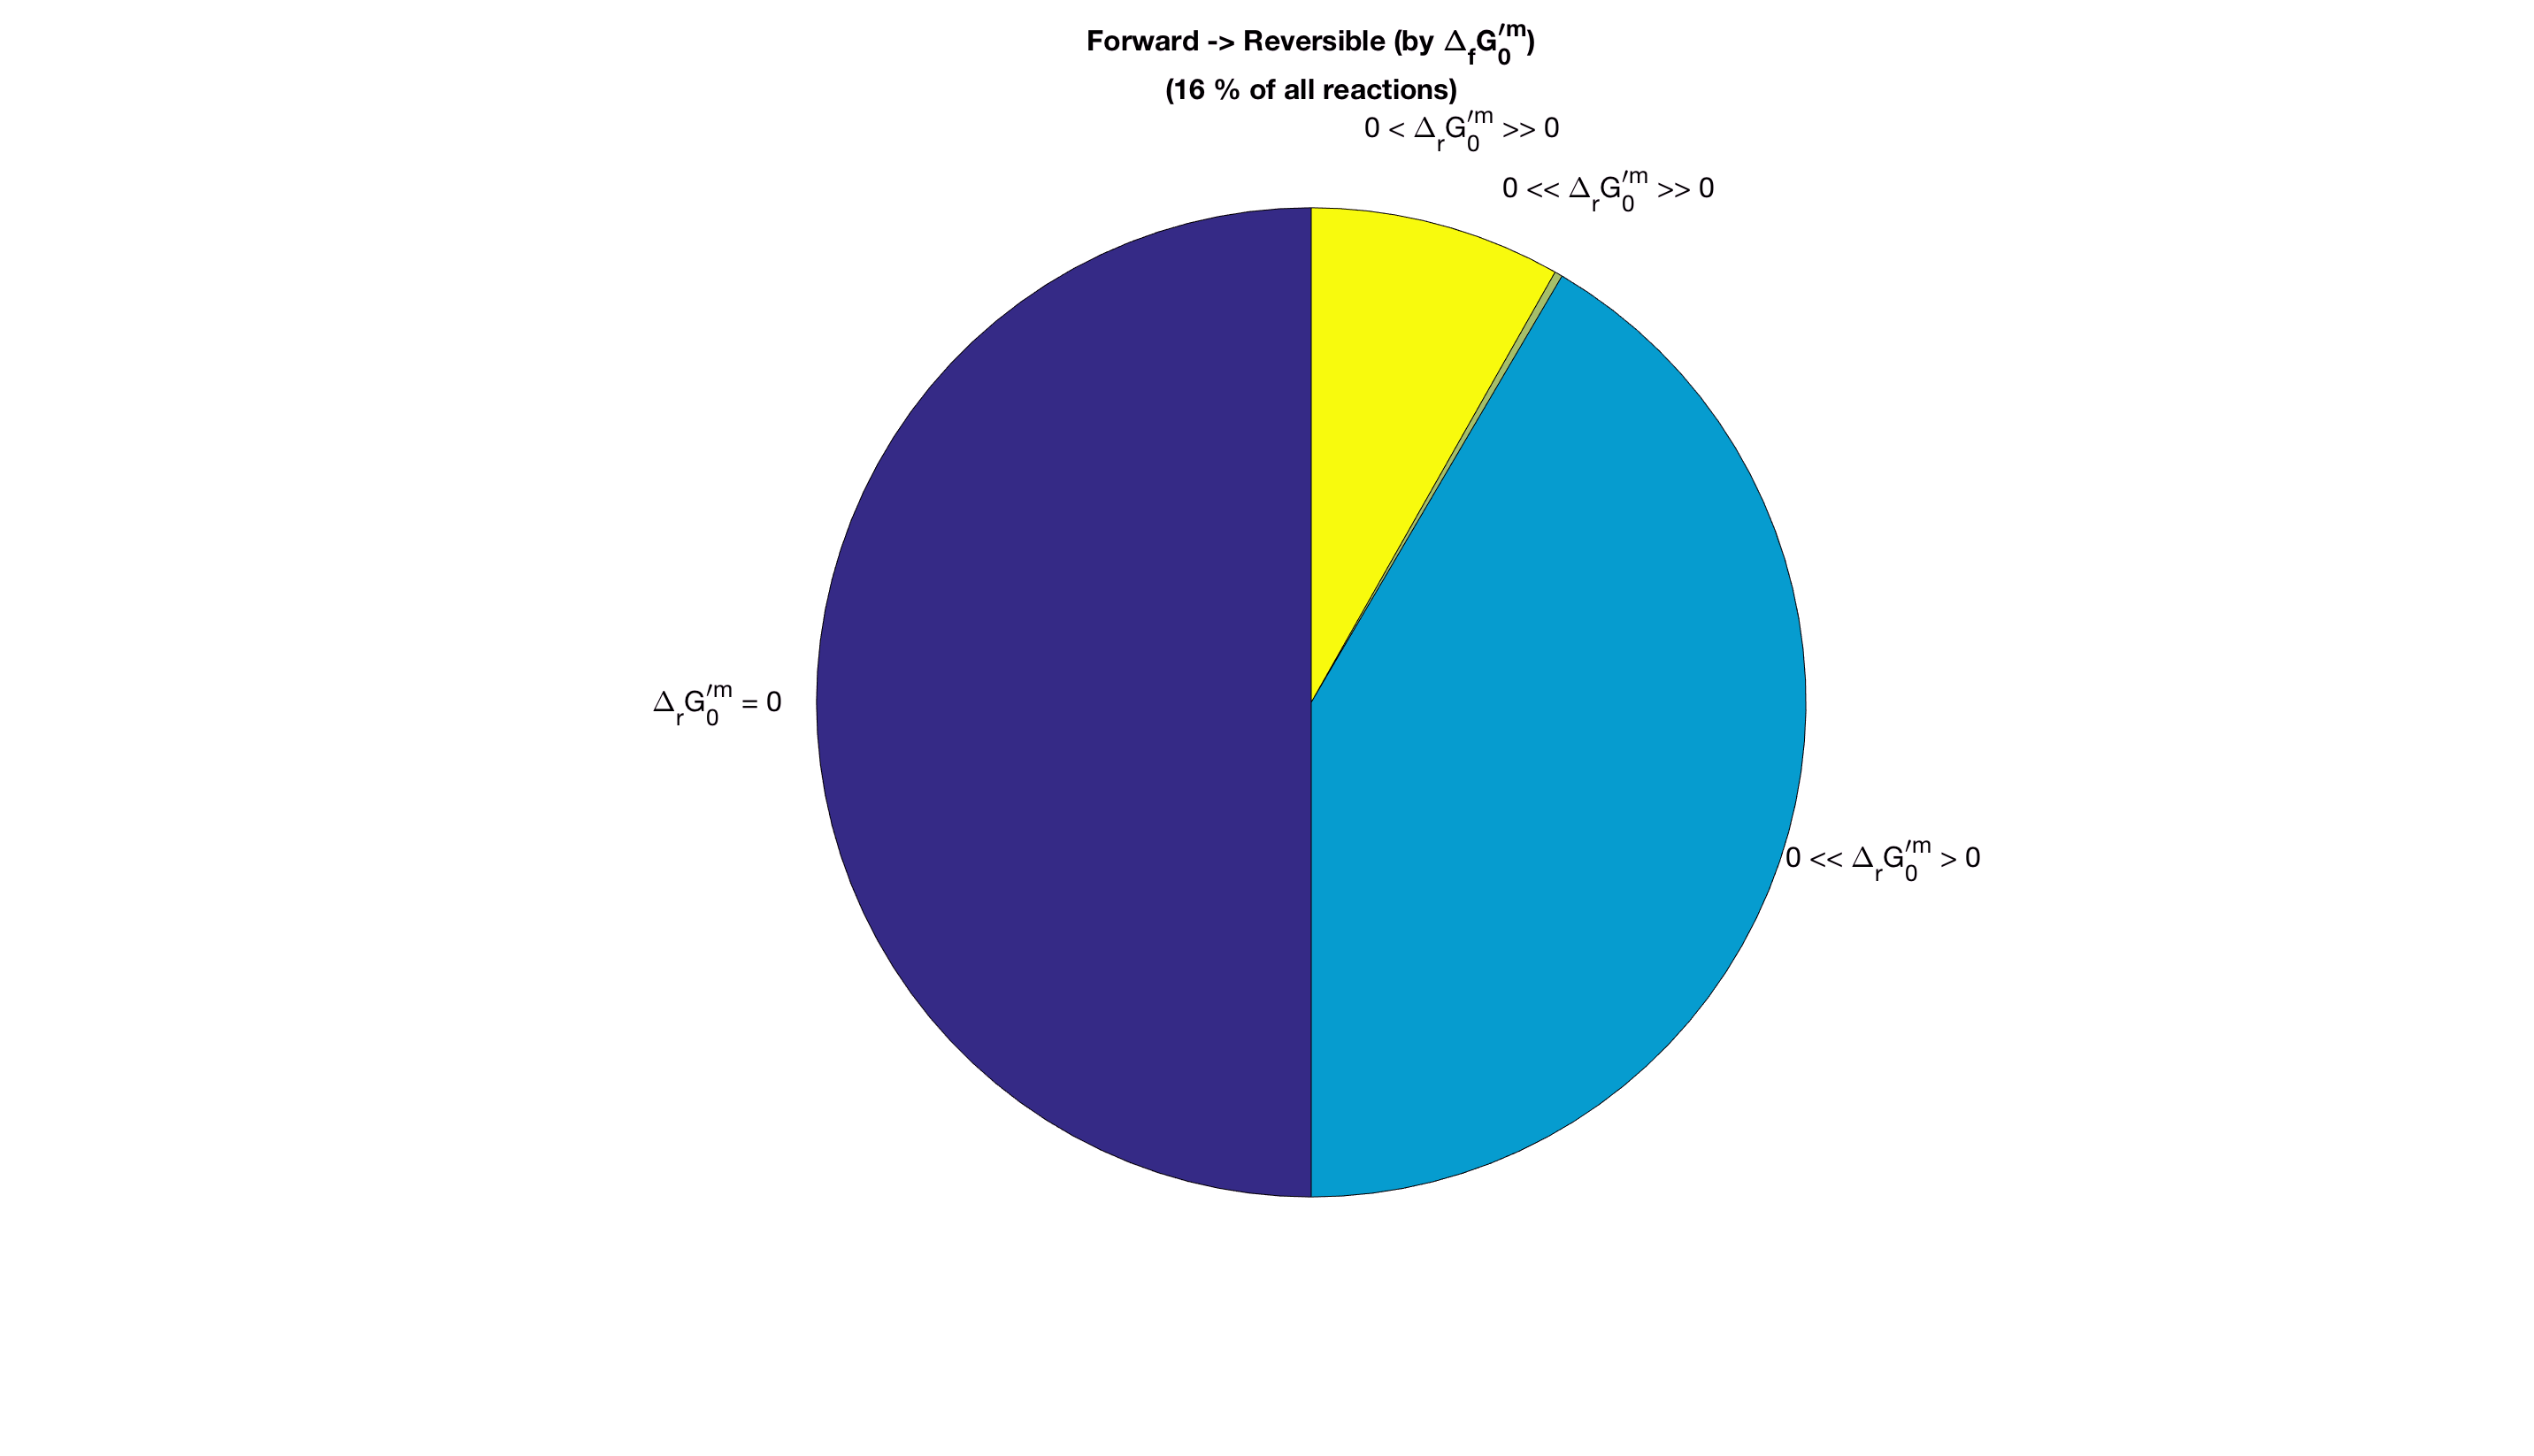

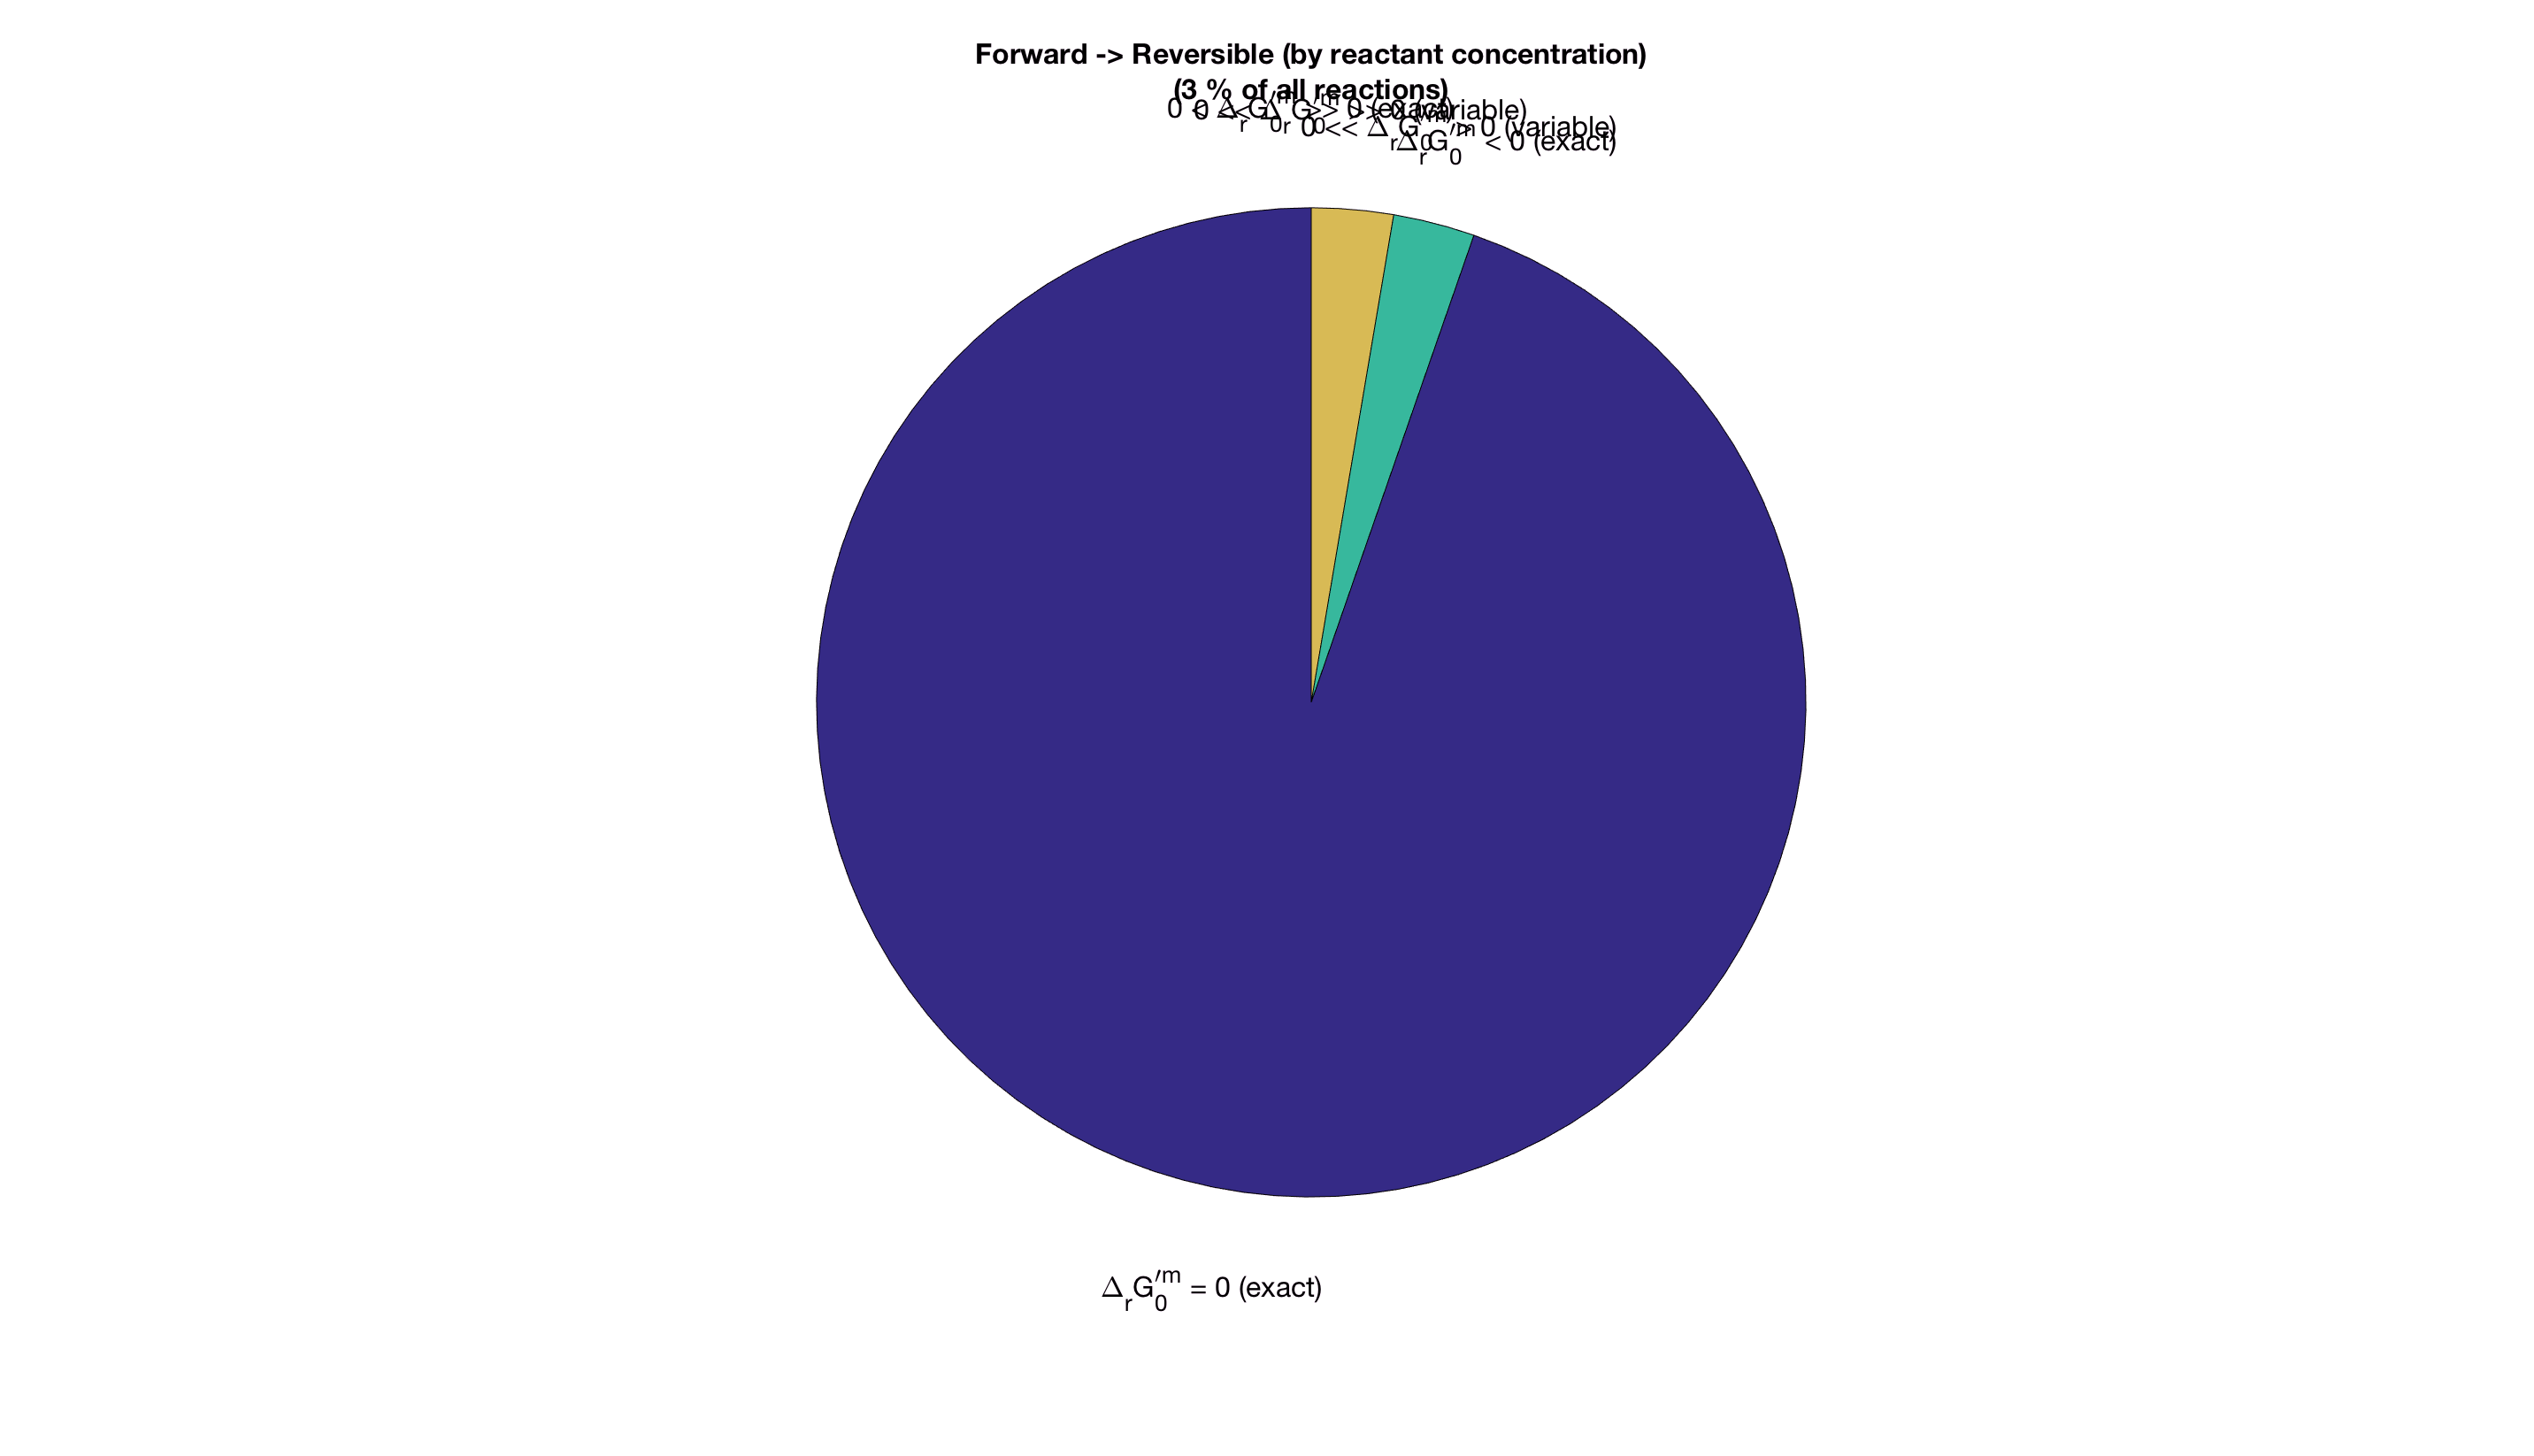

if 1
    fprintf('%s\n','directionalityStatFigures...');
    directionalityStatsFigures(directions,resultsBaseFileName)
end

Generate figures to interpret the overall reasons for reaction directionality changes for the qualitatively forward now quantiatiavely reversible reactions

forwardReversibleFigures...


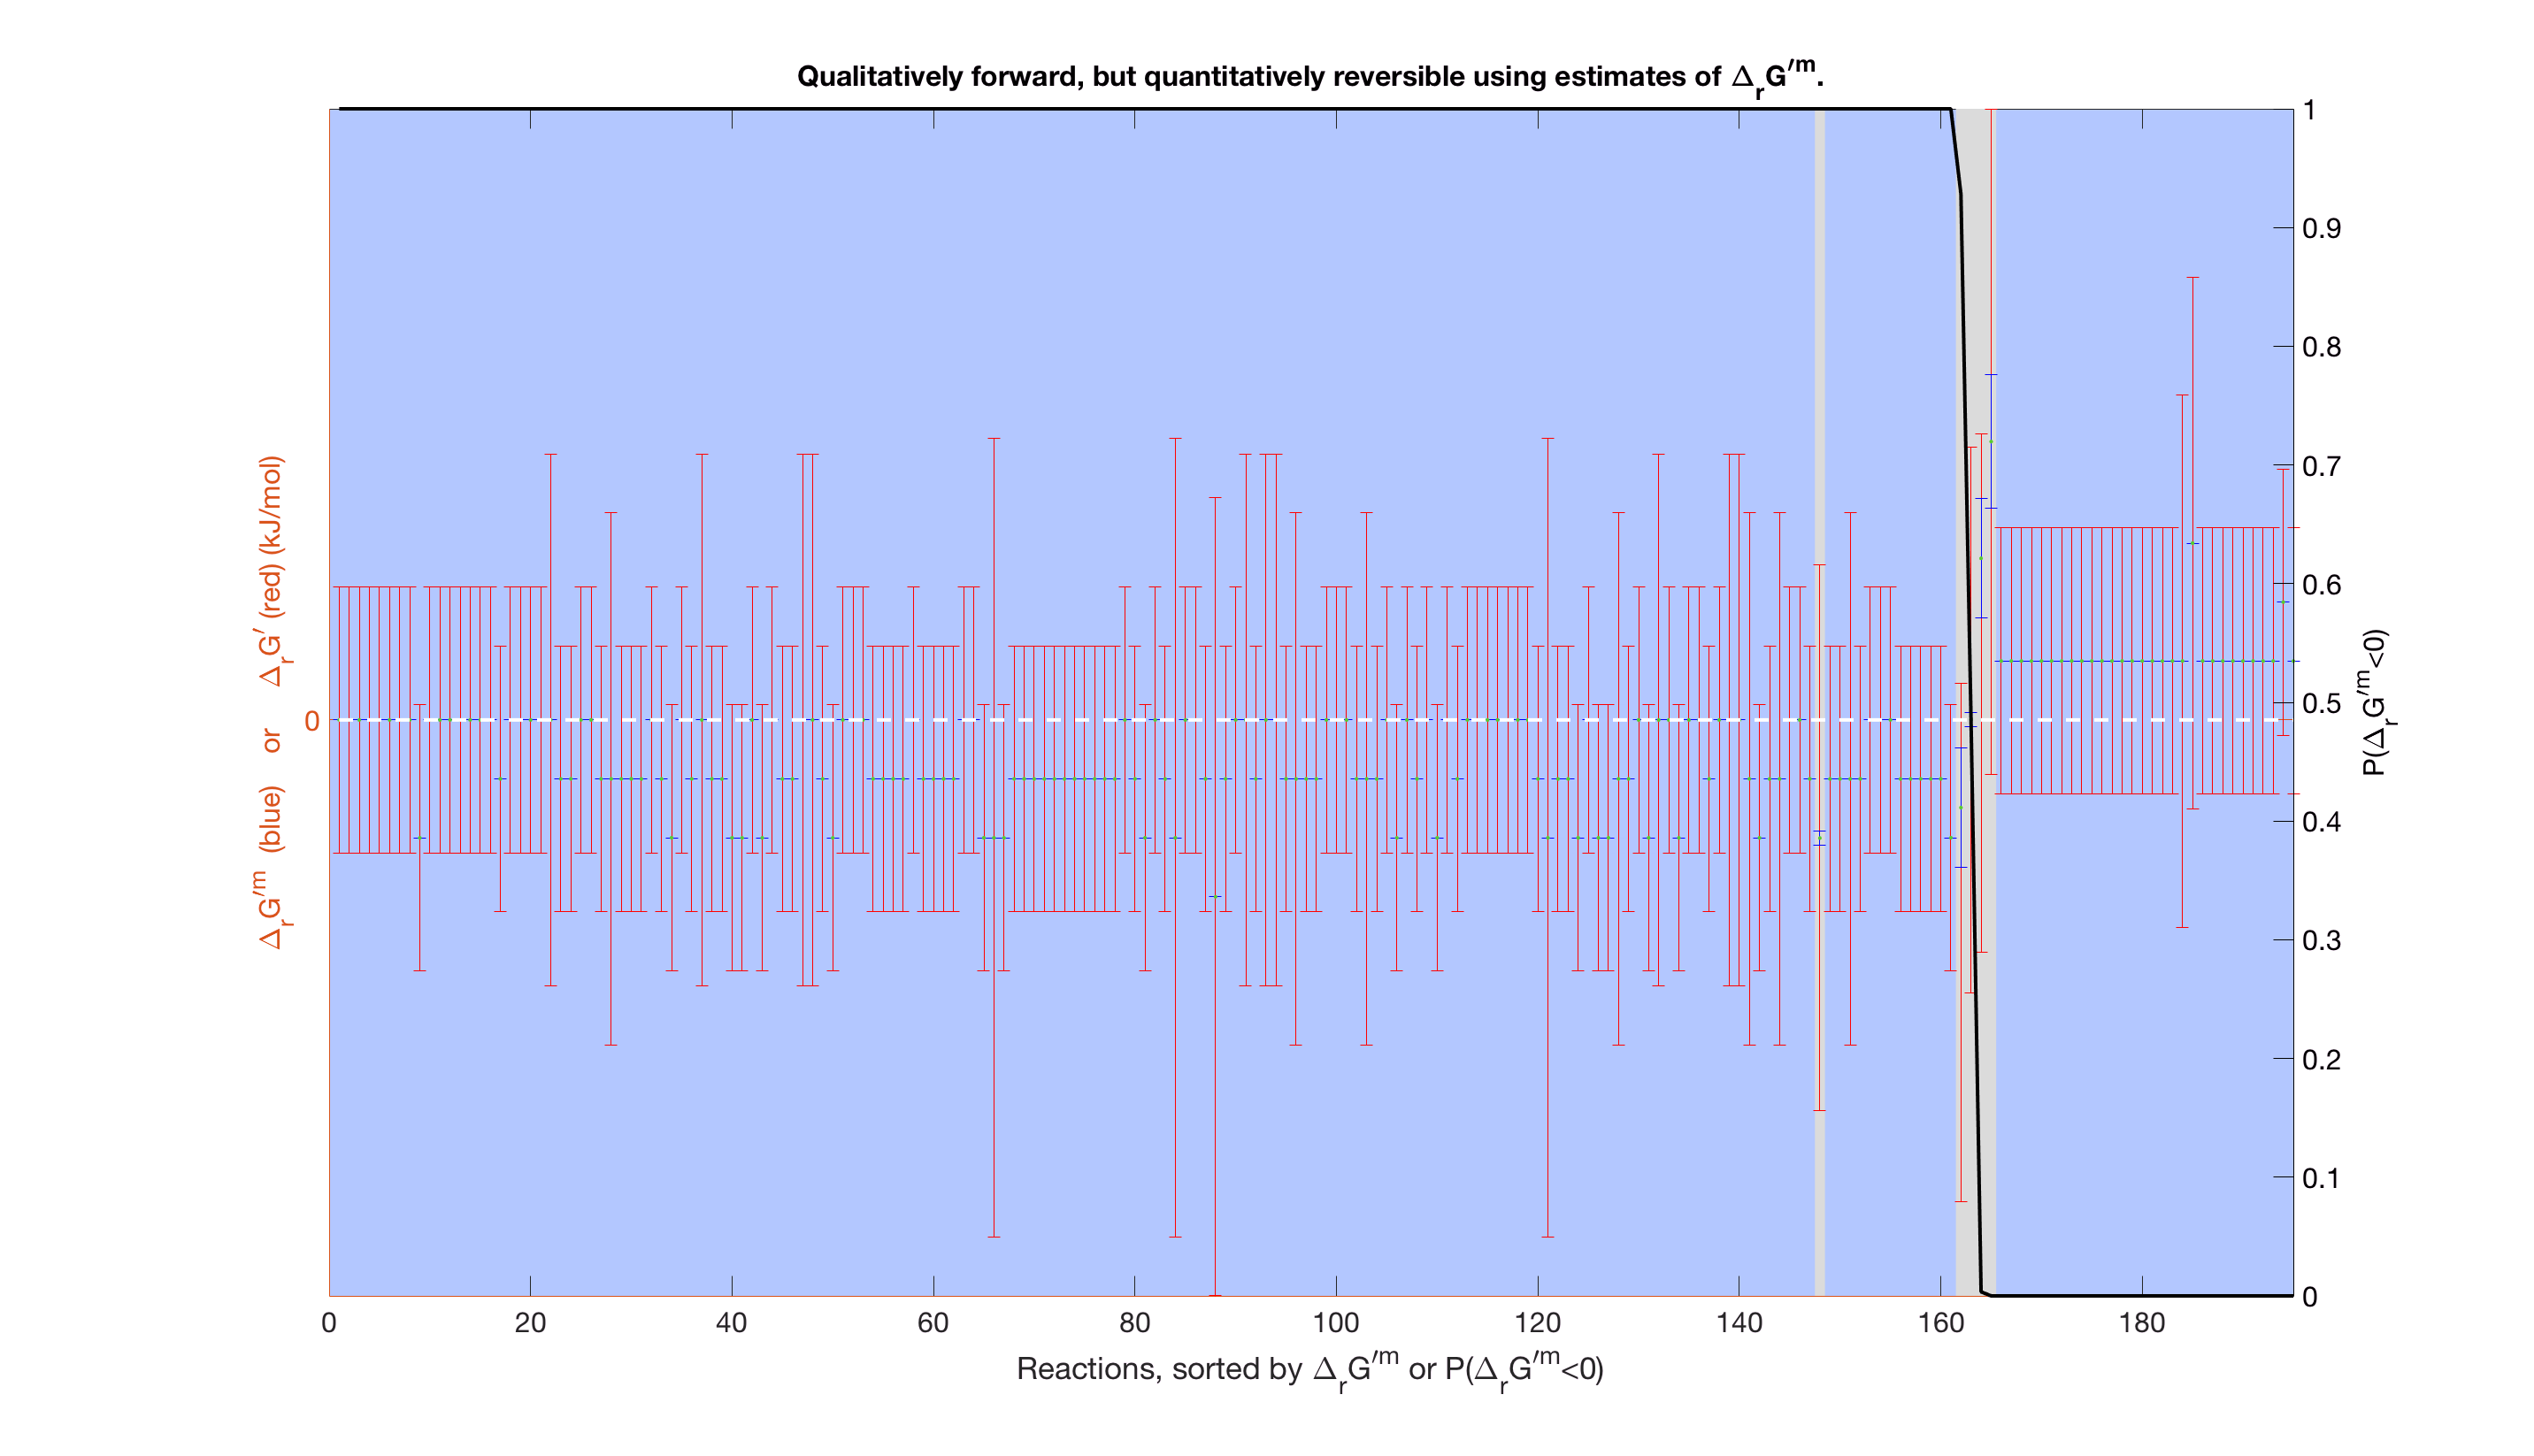

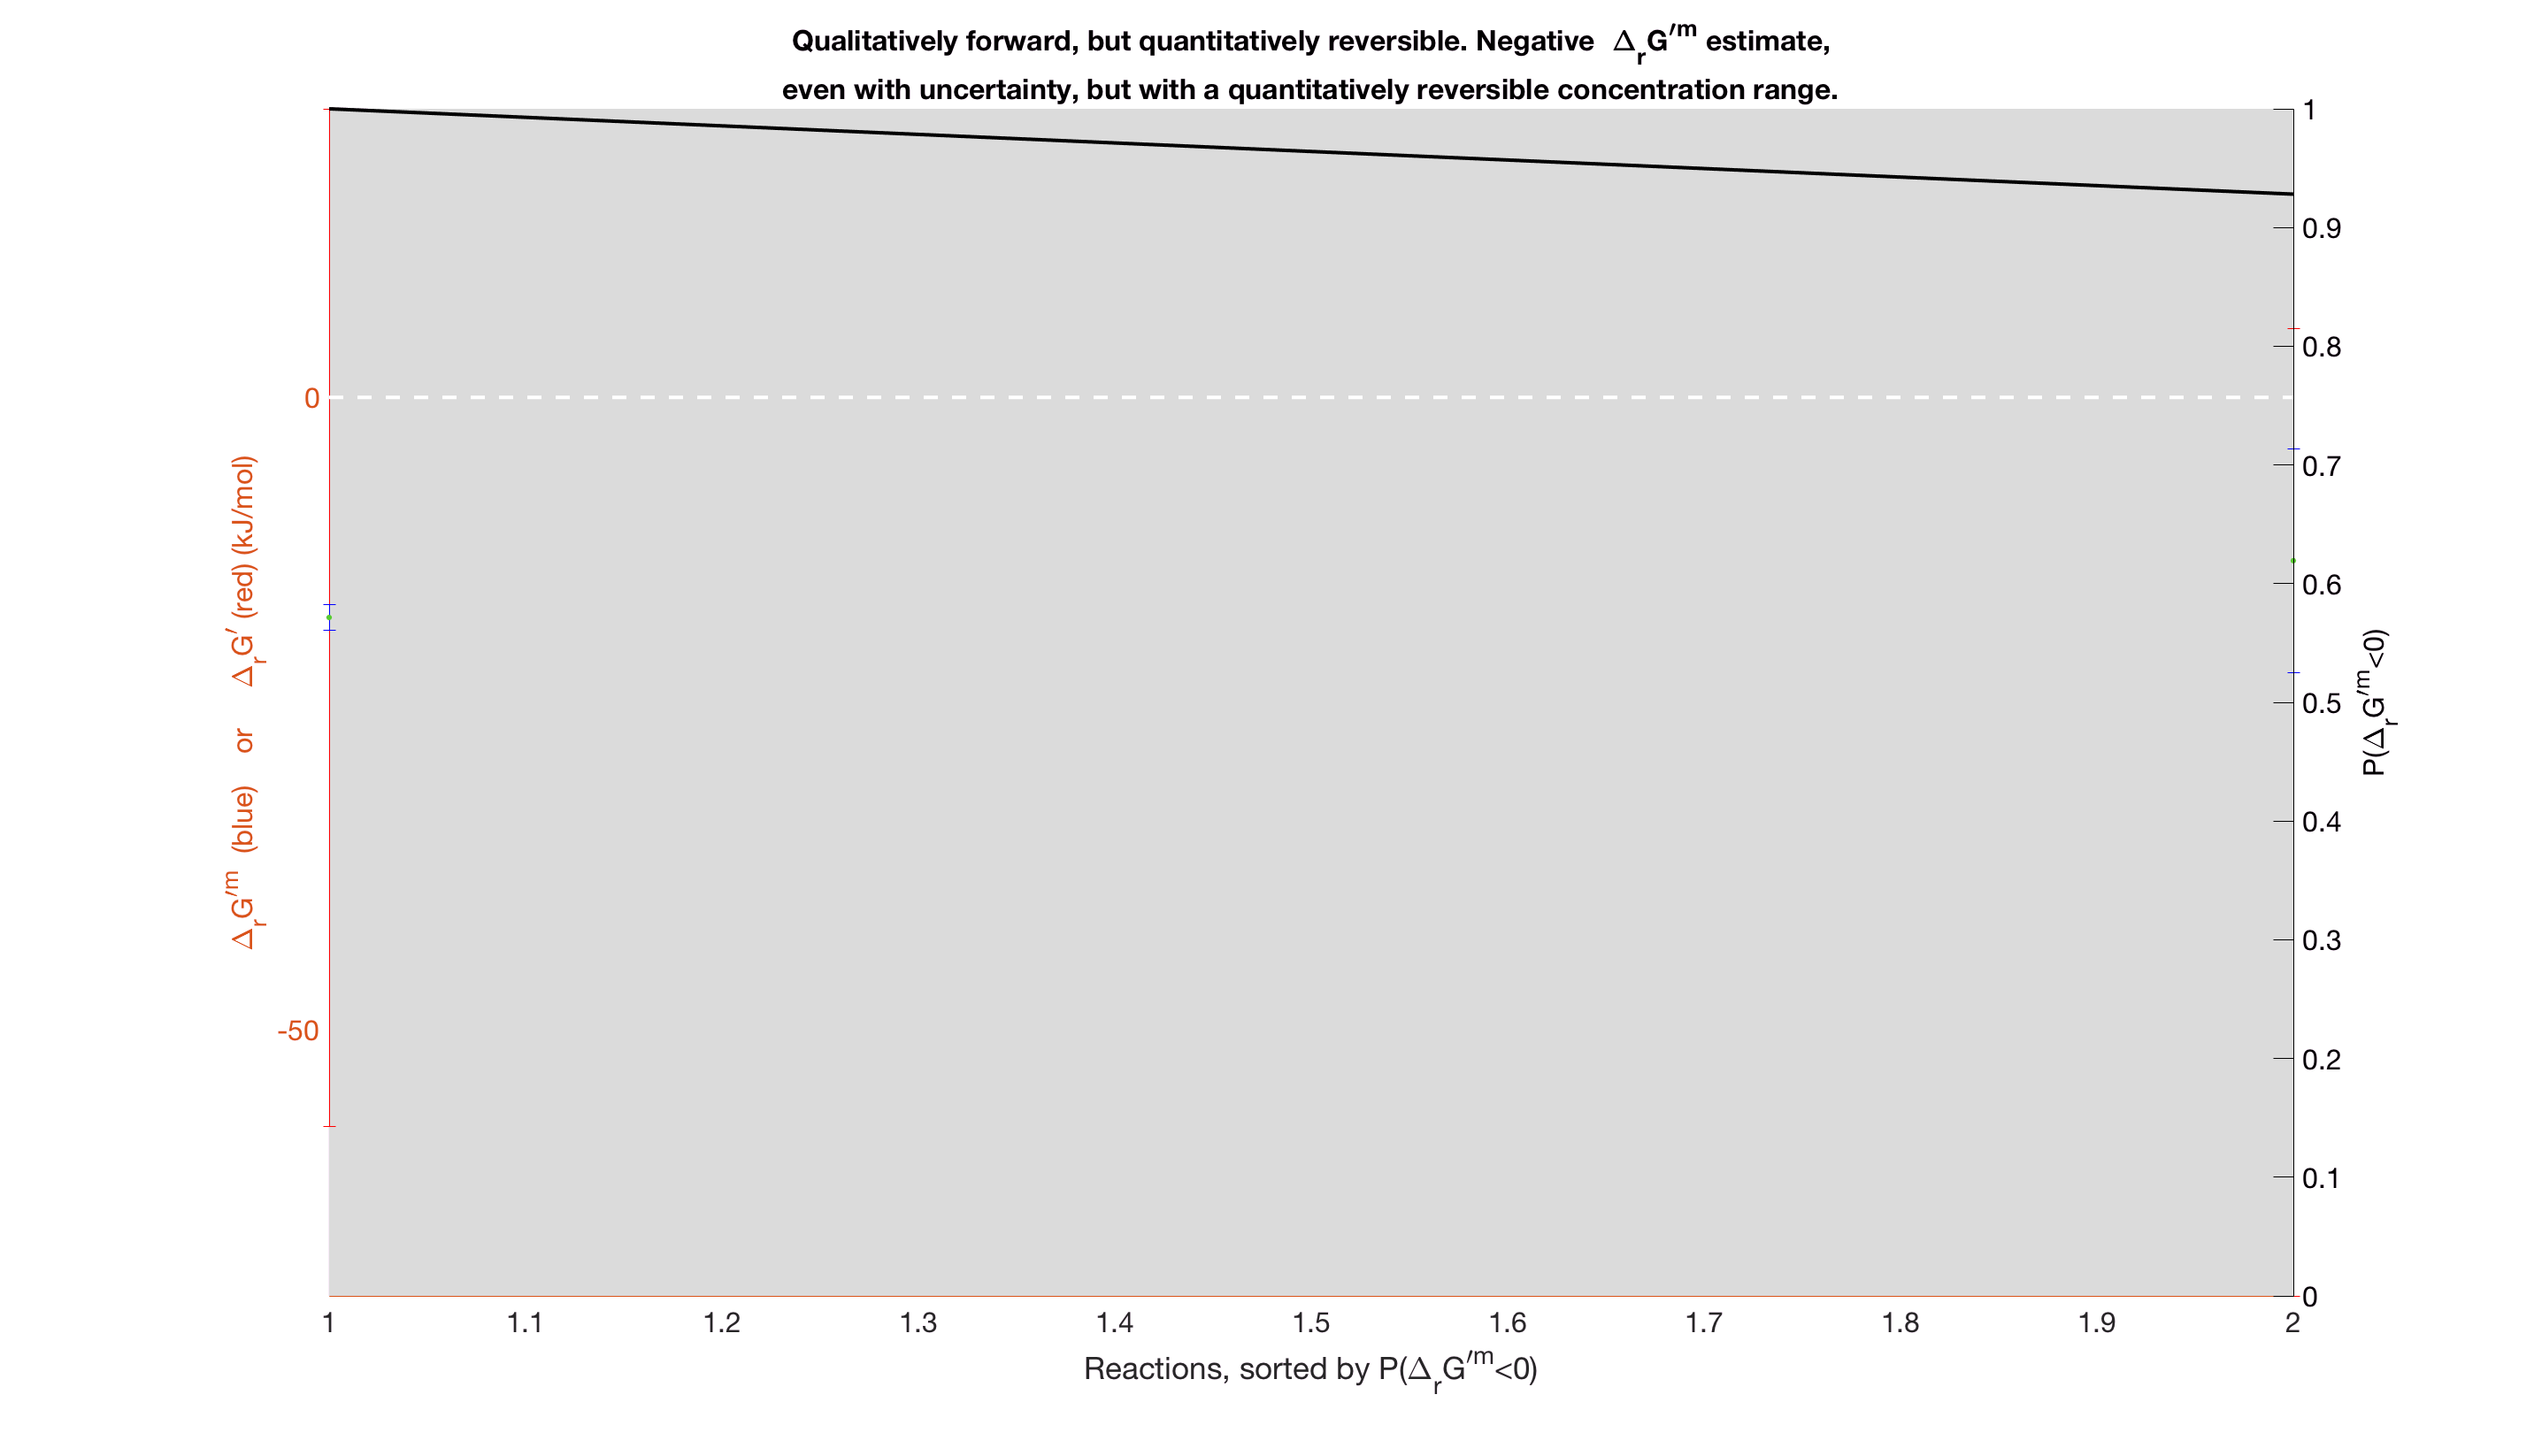

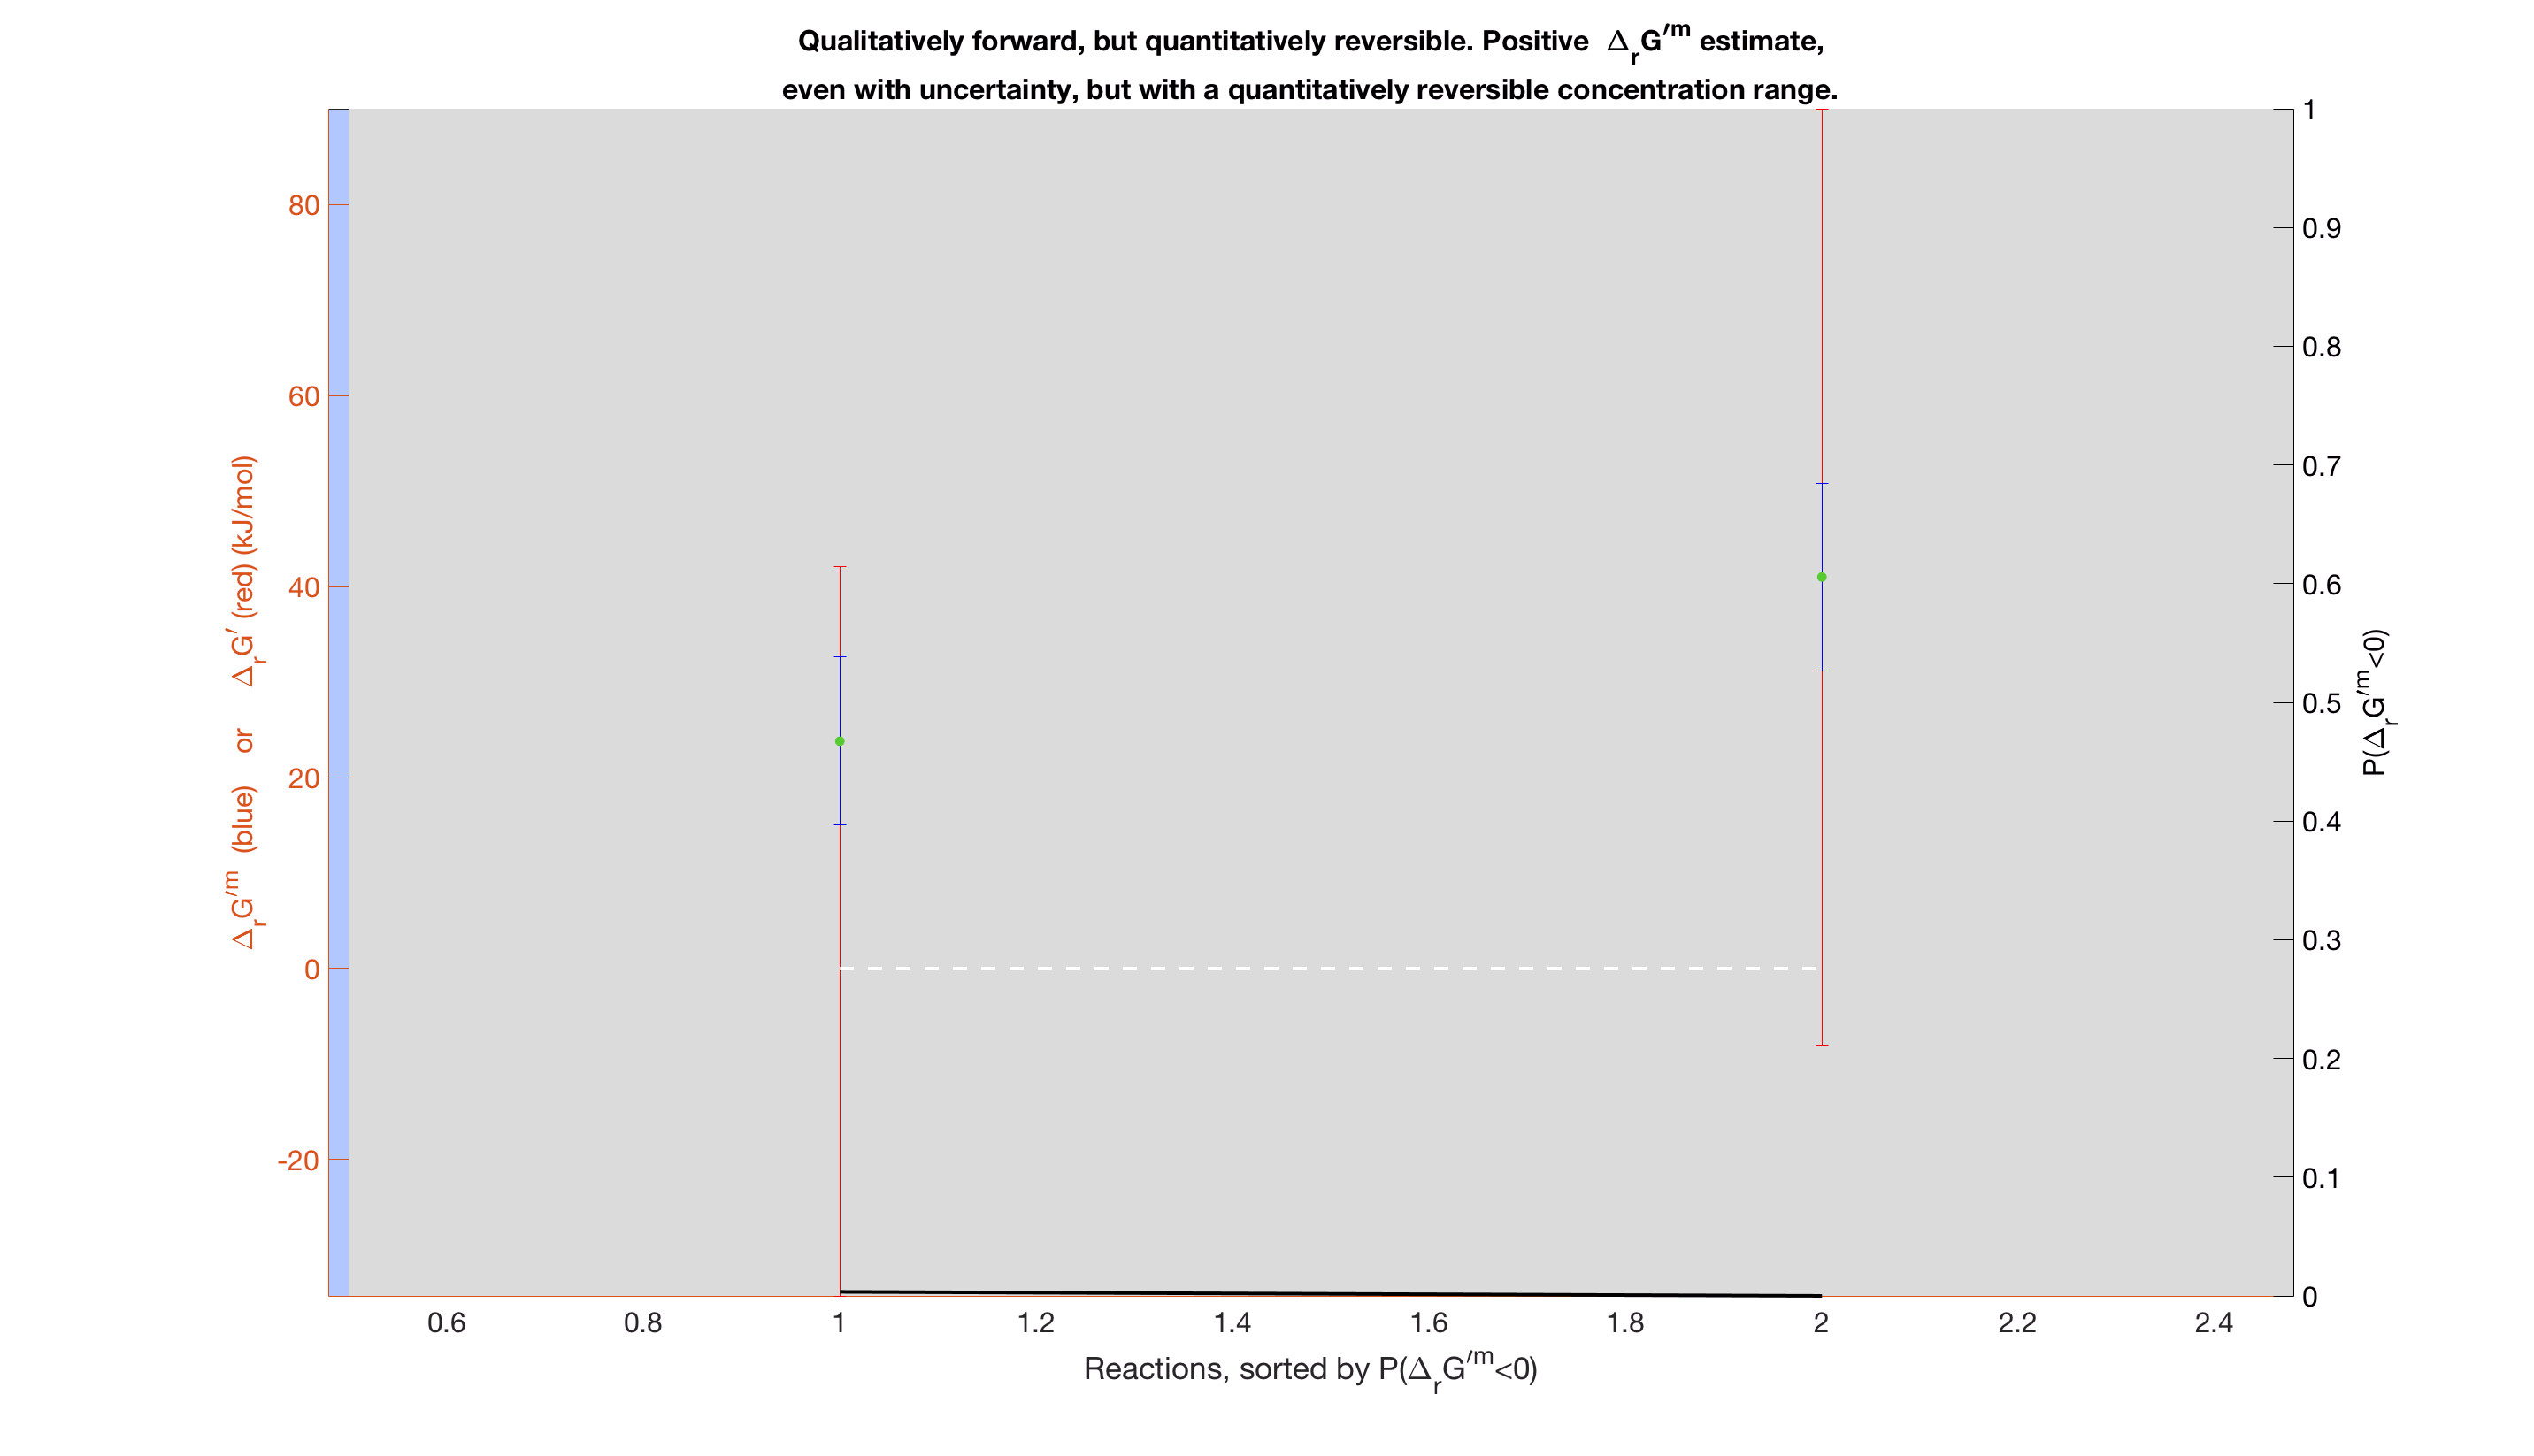

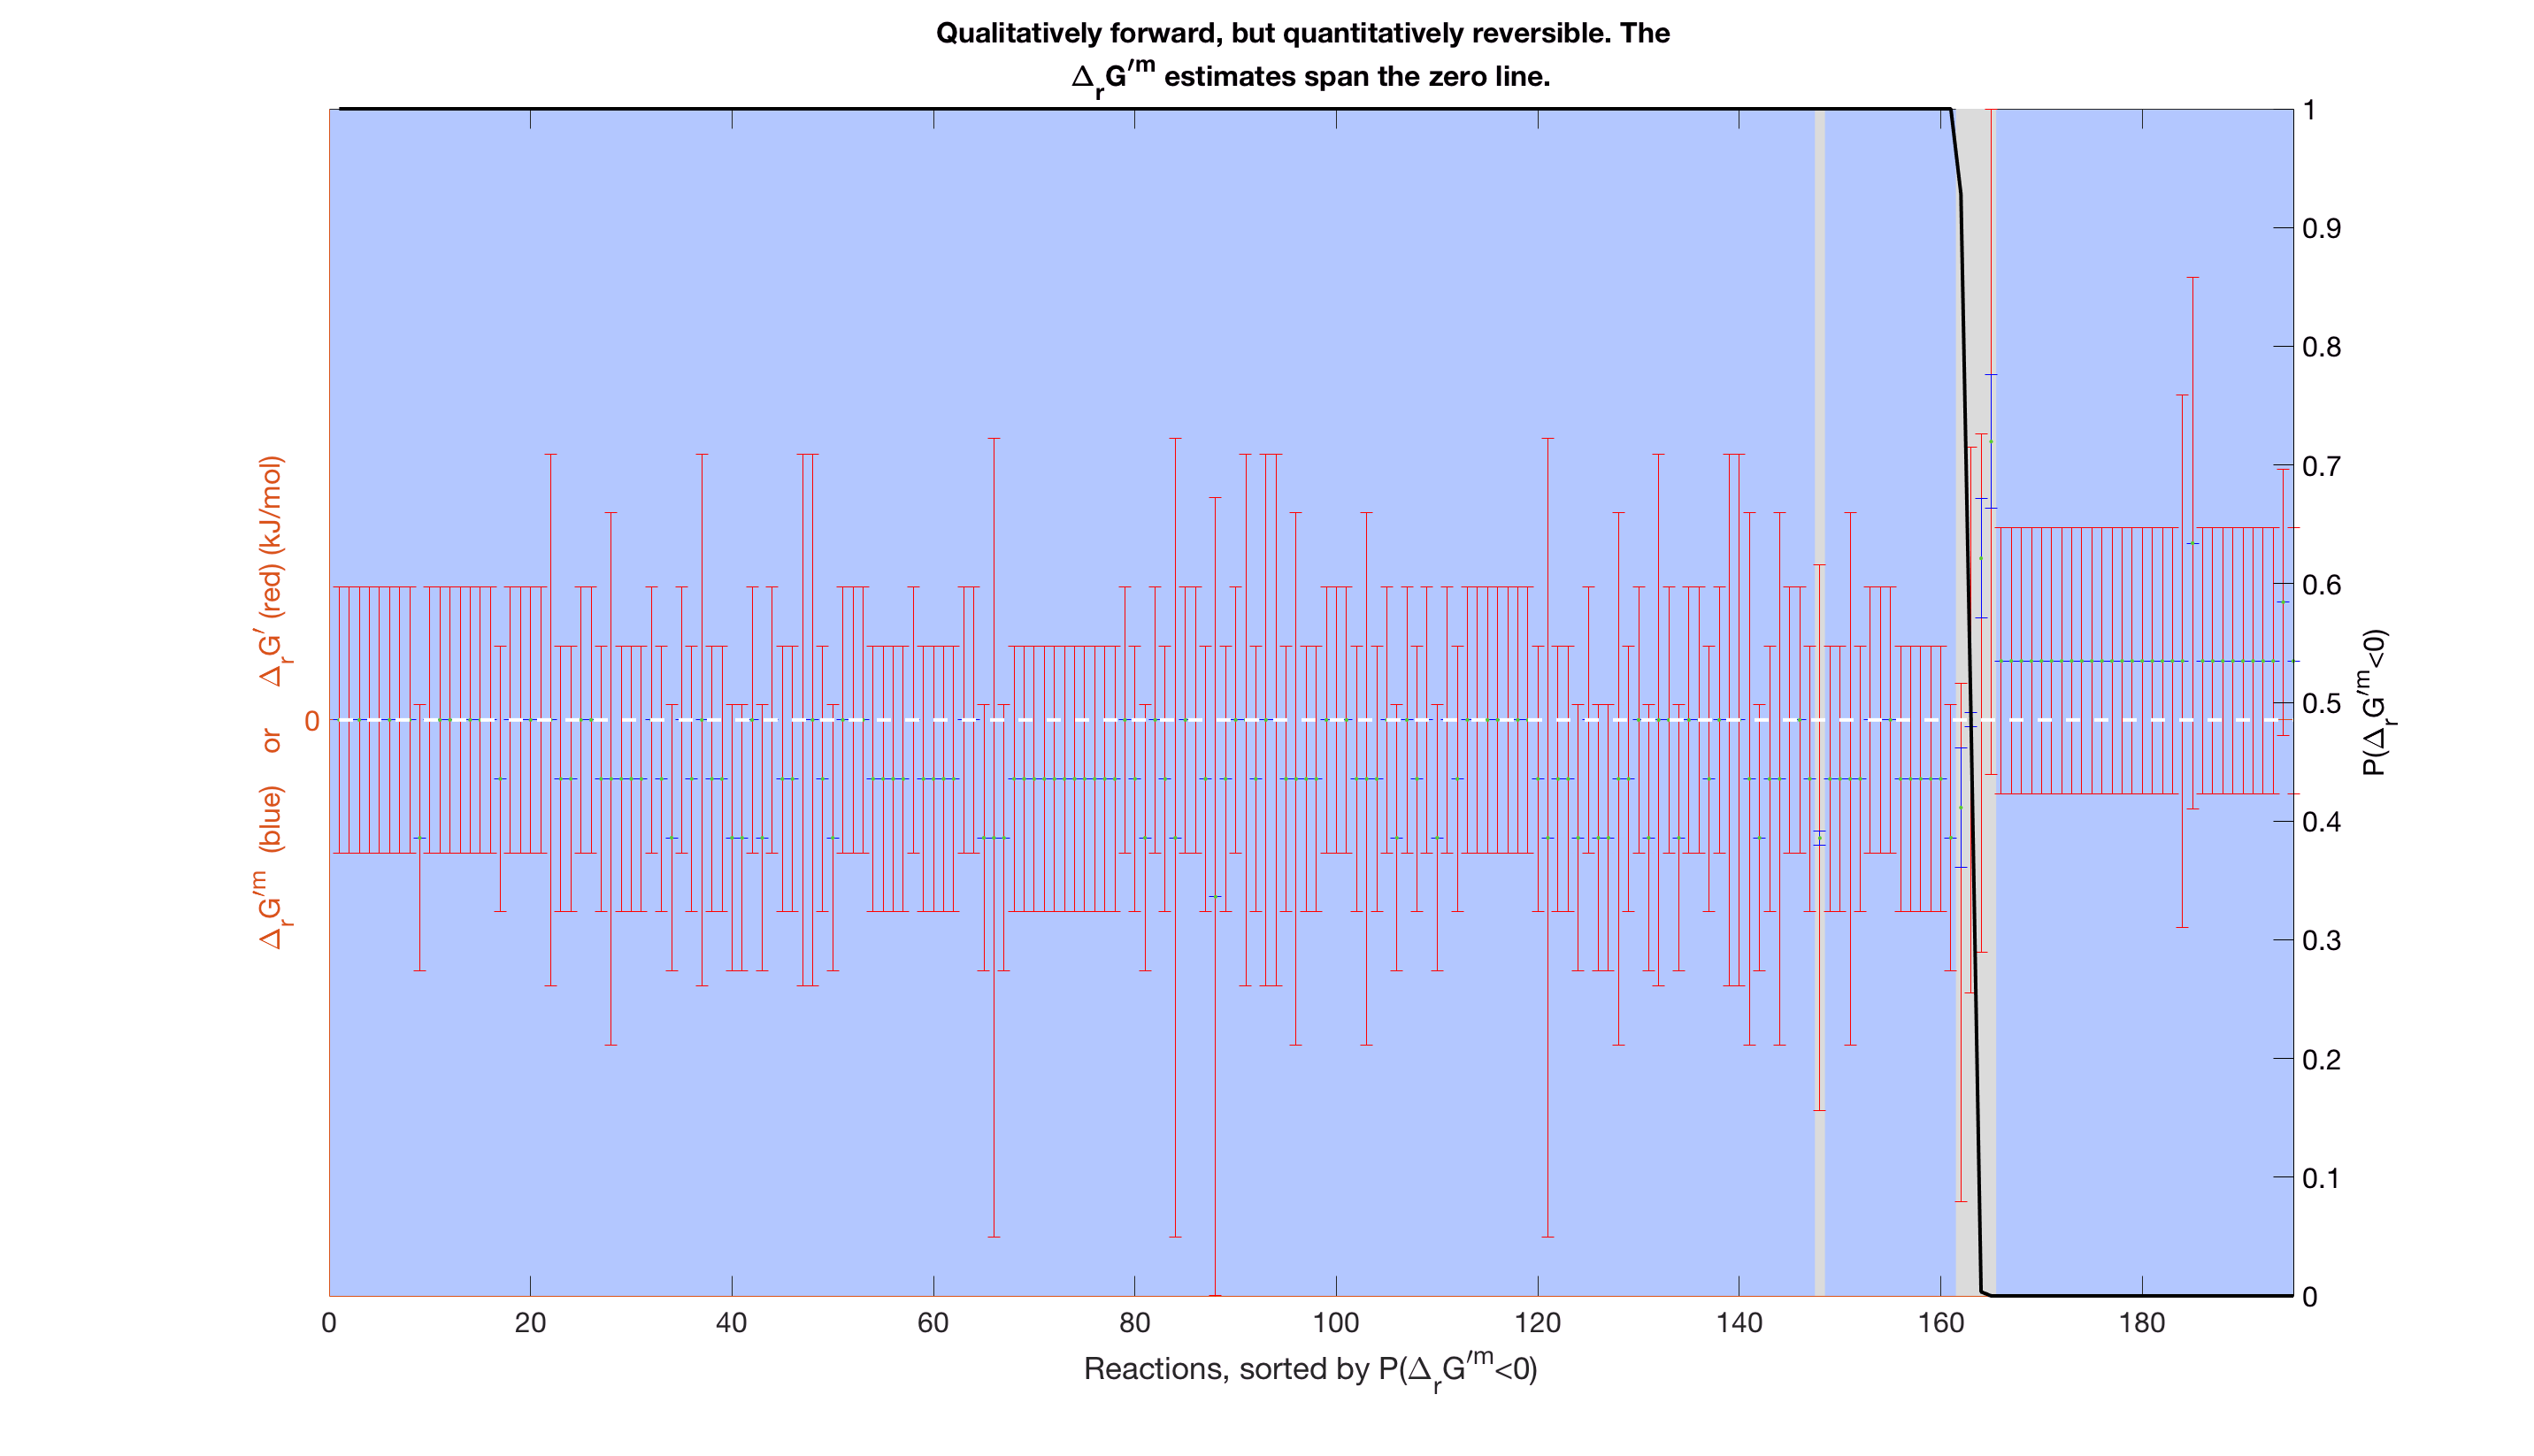

if any(directions.forward2Reversible)
    fprintf('%s\n','forwardReversibleFigures...');
    forwardReversibleFigures(modelThermo,directions,confidenceLevel)
end

Write out tables of experimental and estimated thermochemical parameters for the model

generateThermodynamicTables(modelThermo,resultsBaseFileName);


**REFERENCES**

[1] Fleming, R. M. T. & Thiele, I. von Bertalanffy 1.0: a COBRA toolbox extension to thermodynamically constrain metabolic models. Bioinformatics 27, 142–143 (2011).

[2] Haraldsdóttir, H. S., Thiele, I. & Fleming, R. M. T. Quantitative assignment of reaction directionality in a multicompartmental human metabolic reconstruction. Biophysical Journal 102, 1703–1711 (2012).

[3] Noor, E., Haraldsdóttir, H. S., Milo, R. & Fleming, R. M. T. Consistent Estimation of Gibbs Energy Using Component Contributions. PLoS Comput Biol 9, e1003098 (2013).

[4] Fleming, R. M. T. , Predicat, G.,  Haraldsdóttir, H. S., Thiele, I. von Bertalanffy 2.0 (in preparation).